# Machine Learning: Programming Exercise 3

## Multi-class Classification and Neural Networks

In this exercise, you will implement one-vs-all logistic regression and neural networks to recognize hand-written digits.

### Files needed for this exercise

- `ex3.mlx` - MATLAB Live Script that steps you through the exercise

- `ex3data1.mat` - Training set of hand-written digits

- `ex3weights.mat` - Initial weights for the neural network exercise

- `submit.m `- Submission script that sends your solutions to our servers

- `displayData.m` - Function to help visualize the dataset

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `sigmoid.m` - Sigmoid function

- `*lrCostFunction.m` - Logistic regression cost function

- `*oneVsAll.m` - Train a one-vs-all multi-class classifier

- `*predictOneVsAll.m` - Predict using a one-vs-all multi-class classifier

- `*predict.m `- Neural network prediction function

****indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex3' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                  ex3_companion.mat  fmincg.m           predict.m          
..                 ex3_companion.mlx  lib                predictOneVsAll.m  
displayData.m      ex3data1.mat       lrCostFunction.m   sigmoid.m          
ex3.mlx            ex3weights.mat     oneVsAll.m         submit.m           



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Multi-class Classification

For this exercise, you will use logistic regression and neural networks to recognize handwritten digits (from 0 to 9). Automated handwritten digit recognition is widely used today - from recognizing zip codes (postal codes) on mail envelopes to recognizing amounts written on bank checks. This exercise will show you how the methods you've learned can be used for this classication task. In the first part of the exercise, you will extend your previous implemention of logistic regression and apply it to one-vs-all classification.

### 1.1 Dataset

You are given a data set in `ex3data1.mat` that contains 5000 training examples of handwritten digits*. The .mat format means that that the data has been saved in a native MATLAB matrix format, instead of a text (ASCII) format like a csv-file. These matrices can be read directly into your program by using the load command. After loading, matrices of the correct dimensions and values will appear in your program's memory. The matrix will already be named, so you do not need to assign names to them. 

**This is a subset of the MNIST *[*handwritten digit dataset*](http://yann.lecun.com/exdb/mnist/)

Run the code below to load the data.

% Load saved matrices from file
load('ex3data1.mat');
% The matrices X and y will now be in your MATLAB environment

    There are 5000 training examples in `ex3data1.mat`, where each training example is a 20 pixel by 20 pixel grayscale image of the digit. Each pixel is represented by a floating point number indicating the grayscale intensity at that location. The 20 by 20 grid of pixels is 'unrolled' into a 400-dimensional vector. Each of these training examples becomes a single row in our data matrix `X`. This gives us a 5000 by 400 matrix `X` where every row is a training example for a handwritten digit image.


$$X=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T -\\
-{\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack$$


    The second part of the training set is a 5000-dimensional vector `y` that contains labels for the training set. To make things more compatible with MATLAB indexing, where there is no zero index, we have mapped the digit zero to the value ten. Therefore, a '0' digit is labeled as '10', while the digits '1' to '9' are labeled as '1' to '9' in their natural order.

## 1.2 Visualizing the data

You will begin by visualizing a subset of the training set. The code below randomly selects selects 100 rows from `X` and passes those rows to the `displayData` function. This function maps each row to a 20 pixel by 20 pixel grayscale image and displays the images together. We have provided the `displayData` function, and you are encouraged to examine the code to see how it works. After you run this step, you should see an image like Figure 1.

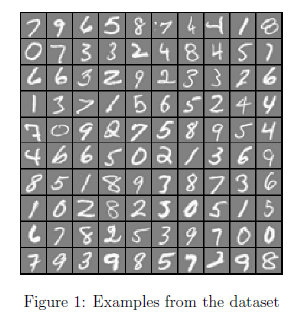                        

m = size(X, 1);
% Randomly select 100 data points to display
rand_indices = randperm(m);
sel = X(rand_indices(1:100), :);
displayData(sel);

### 1.3 Vectorizing logistic regression

You will be using multiple one-vs-all logistic regression models to build a multi-class classifier. Since there are 10 classes, you will need to train 10 separate logistic regression classifiers. To make this training efficient, it is important to ensure that your code is well vectorized. In this section, you will implement a vectorized version of logistic regression that does not employ any `for` loops. You can use your code in the last exercise as a starting point for this exercise.

#### 1.3.1 Vectorizing the cost function

We will begin by writing a vectorized version of the cost function. Recall that in (unregularized) logistic regression, the cost function is


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1-y^{(i)}) \log(1- h_{\theta}(x^{(i)}))\right],$$


To compute each element in the summation, we have to compute $h_{\theta}(x^{(i)})$ for every example $i$, where $h_{\theta}(x^{(i)}) = g(\theta^T x^{(i)})$ and $g(z) =\frac{1}{1+e^{-z}}$ is the sigmoid function. It turns out that we can compute this quickly for all our examples by using matrix multiplication. Let us define $X$ and $\theta$ as


$$X\theta \;=\left\lbrack \begin{array}{c}
-{\left(x^{\left(1\right)} \right)}^T \theta \;-\\
-{\left(x^{\left(2\right)} \right)}^T \theta \;-\\
\vdots \\
-{\left(x^{\left(m\right)} \right)}^T \theta \;-
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-\;\theta^T \left(x^{\left(1\right)} \right)-\\
-{\;\theta }^T \left(x^{\left(2\right)} \right)\;-\\
\vdots \\
-{\;\theta }^T \left(x^{\left(m\right)} \right)-
\end{array}\right\rbrack \;$$


In the last equality, we used the fact that $a^T b= b^T a$ if $a$ and $b$ are vectors. This allows us to compute the products $\theta^T x^{(i)}$ for all our examples $i$ in one line of code.

    Your job is to write the unregularized cost function in the file `lrCostFunction.m `Your implementation should use the strategy we presented above to calculate $\theta^T x^{(i)}$. You should also use a vectorized approach for the rest of the cost function. A fully vectorized version of `lrCostFunction.m` should not contain any loops. (Hint: You might want to use the element-wise multiplication operation (`.*`) and the sum operation `sum` when writing this function)

#### 1.3.2 Vectorizing the gradient

Recall that the gradient of the (unregularized) logistic regression cost is a vector where the $j$th element is defined as 


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}
$$


To vectorize this operation over the dataset, we start by writing out all the partial derivatives explicitly for all $\theta_j$,

$\left[ \begin{array}{c} 
\frac{\partial J(\theta)}{\partial \theta_0} \\
\frac{\partial J(\theta)}{\partial \theta_1} \\
\frac{\partial J(\theta)}{\partial \theta_2} \\
\vdots \\
\frac{\partial J(\theta)}{\partial \theta_n}   
 \end{array} \right]
 = \frac{1}{m}
\left[ \begin{array}{c} 
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_0^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_1^{(i)} \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_2^{(i)} \\
\vdots \\
\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_n^{(i)}
\end{array}\right] =\frac{1}{m} \sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x^{(i)} =
\frac{1}{m}X^T {\left( h_\theta(x)-y\right)}
$   (1)

where


$$h_{\theta \;} \left(x\right)-y=\left\lbrack \begin{array}{c}
h_{\theta \;} \left(x^{\left(1\right)} \right)-y^{\left(1\right)} \\
h_{\theta \;} \left(x^{\left(2\right)} \right)-y^{\left(2\right)} \\
\vdots \\
h_{\theta \;} \left(x^{\left(m\right)} \right)-y^{\left(m\right)} 
\end{array}\right\rbrack$$


    Note that $x^{(i)}$ is a vector, while $(h_\theta(x^{(i)})-y^{(i)})$ is a scalar (single number). To understand the last step of the derivation, let $\beta_i = (h_\theta(x^{(i)})-y^{(i)})$ and observe that:


$$\sum_i \beta_i x^{\left(i\right)} =\left\lbrack \begin{array}{cccc}
| & | & \; & |\\
x^{\left(1\right)}  & x^{\left(2\right)}  & \dots  & x^{\left(m\right)} \\
| & | & \; & |
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\beta_1 \\
\beta_2 \\
\vdots \\
\beta_m 
\end{array}\right\rbrack =X^T \beta ,$$


    The expression above allows us to compute all the partial derivatives without any loops. If you are comfortable with linear algebra, we encourage you to work through the matrix multiplications above to convince yourself that the vectorized version does the same computations. You should now implement Equation (1) to compute the correct vectorized gradient. Once you are done, complete the function `lrCostFunction.m` by implementing the gradient.

**Debugging Tip: **Vectorizing code can sometimes be tricky. One common strategy for debugging is to print out the sizes of the matrices you are working with using the size function. For example, given a data matrix $X$ of size 100 x 20 (100 examples, 20 features) and $\theta$, a vector with dimensions 20 x 1, you can observe that $X\theta$ is a valid multiplication operation, while $\theta X$ is not. Furthermore, if you have a non-vectorized version of your code, you can compare the output of your vectorized code and non-vectorized code to make sure that they produce the same outputs.

#### 1.3.3 Vectorizing regularized logistic regression

After you have implemented vectorization for logistic regression, you will now add regularization to the cost function. Recall that for regularized logistic regression, the cost function is defined as


$$J(\theta) =\frac{1}{m}\sum_{i=1}^m{\left[

-y^{(i)} \log(h_{\theta}(x^{(i)}))- (1 -y^{(i)}) \log(1-h_{\theta}(x^{(i)}))\right]+\frac{\lambda}{2m}\sum_{j=1}^n{\theta_j^2}$$


Note that you should not be regularizing $\theta_0$ which is used for the bias term. Correspondingly, the partial derivative of regularized logistic regression cost for $\theta_j$ is defined as


$$\frac{\partial J(\theta)}{\partial \theta_j} = \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}\qquad \mathrm{for}\;j=0,
$$



$$\frac{\partial J(\theta)}{\partial \theta_j} = \left( \frac{1}{m}\sum_{i=1}^m{\left( h_\theta(x^{(i)})-y^{(i)}\right)x_j^{(i)}} \right)+\frac{\lambda}{m}\theta_j\qquad \mathrm{for}\;j\geq1$$


Now modify your code in `lrCostFunction` to account for regularization. Once again, you should not put any loops into your code. When you are finished, run the code below to test your vectorized implementation and compare to expected outputs:

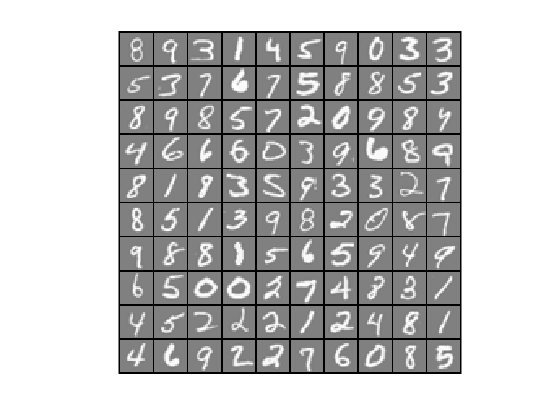

theta_t = [-2; -1; 1; 2];
X_t = [ones(5,1) reshape(1:15,5,3)/10];
y_t = ([1;0;1;0;1] >= 0.5);
lambda_t = 3;
[J, grad] = lrCostFunction(theta_t, X_t, y_t, lambda_t);


fprintf('Cost: %f | Expected cost: 2.534819\n',J);
fprintf('Gradients:\n'); fprintf('%f\n',grad);
fprintf('Expected gradients:\n 0.146561\n -0.548558\n 0.724722\n 1.398003');

**MATLAB Tip:** When implementing the vectorization for regularized logistic regression, you might often want to only sum and update certain elements of $\theta$. In MATLAB, you can index into the matrices to access and update only certain elements. For example, `A(:,3:5)= B(:, 1:3)` will replace columns 3 to 5 of `A` with the columns 1 to 3 from `B`. One special keyword you can use in indexing is the `end` keyword in indexing. This allows us to select columns (or rows) until the end of the matrix. For example, `A(:, 2:end)` will only return elements from the 2nd to last column of `A`. Thus, you could use this together with the `sum` and `.^` operations to compute the sum of only the elements you are interested in (e.g. `sum(z(2:end).^2))`. In the starter code,` lrCostFunction.m`, we have also provided hints on yet another possible method computing the regularized gradient.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 1.4 One-vs-all classication

In this part of the exercise, you will implement one-vs-all classification by training multiple regularized logistic regression classifiers, one for each of the $K$ classes in our dataset (Figure 1). In the handwritten digits dataset, $K = 10$, but your code should work for any value of $K$. 

    You should now complete the code in `oneVsAll.m` to train one classifier for each class. In particular, your code should return all the classifier parameters in a matrix $\Theta \in \mathbb{R}^{K\times(N+1)}$, where each row of $\Theta$ corresponds to the learned logistic regression parameters for one class. You can do this with a `for` loop from 1 to `K`, training each classifier independently.

Note that the `y` argument to this function is a vector of labels from 1 to 10, where we have mapped the digit '0' to the label 10 (to avoid confusions with indexing). When training the classifier for class $k \in \{1,\ldots,K\},$ you will want a $m$-dimensional vector of labels $y,$ where $y_j\in \{0,\;1\}$ indicates whether the $j$-th training instance belongs to class $k\; (y_j = 1)$, or if it belongs to a different class $(y_j = 0).$ You may find logical arrays helpful for this task.

**MATLAB Tip**: Logical arrays in MATLAB are arrays which contain binary (0 or 1) elements. In MATLAB, evaluating the expression `a == b` for a vector `a` (of size $m\times1$) and scalar `b` will return a vector of the same size as `a` with ones at positions where the elements of `a` are equal to `b` and zeroes where they are different. To see how this works for yourself, run the following code:

a = 1:10; % Create a and b
b = 3;
disp(a == b) % You should try different values of b here

Furthermore, you will be using `fmincg` for this exercise (instead of `fminunc`). `fmincg` works similarly to `fminunc`, but is more more efficient for dealing with a large number of parameters. After you have correctly completed the code for `oneVsAll.m`, run the code below to use your `oneVsAll` function to train a multi-class classifier.

num_labels = 10; % 10 labels, from 1 to 10 
lambda = 0.1;

J = 2.5348

grad =     0.1466
   -0.5486
    0.7247
    1.3980


[all_theta] = oneVsAll(X, y, num_labels, lambda);

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 1.4.1 One-vs-all prediction

After training your one-vs-all classifier, you can now use it to predict the digit contained in a given image. For each input, you should compute the 'probability' that it belongs to each class using the trained logistic regression classifiers. Your one-vs-all prediction function will pick the class for which the corresponding logistic regression classifier outputs the highest probability and return the class label $(1, 2,..., \text{ or } K)$ as the prediction for the input example.

    You should now complete the code in `predictOneVsAll.m` to use the one-vs-all classifier to make predictions. Once you are done, run the code below to call your `predictOneVsAll` function using the learned value of $\Theta$. You should see that the training set  accuracy is about 94.9% (i.e., it classifies 94.9% of the examples in the training set correctly).

pred = predictOneVsAll(all_theta, X);

Cost: 2.534819 | Expected cost: 2.534819


fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

Gradients:
0.146561
-0.548558
0.724722
1.398003


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## 2. Neural Networks

In the previous part of this exercise, you implemented multi-class logistic regression to recognize handwritten digits. However, logistic regression cannot form more complex hypotheses as it is only a linear classier. (You could add more features such as polynomial features to logistic regression, but that can be very expensive to train*.) *In this part of the exercise, you will implement a neural network to recognize handwritten digits using the same training set as before. The neural network will be able to represent complex models that form non-linear hypotheses. 

    For this week, you will be using parameters from a neural network that we have already trained. Your goal is to implement the feedforward propagation algorithm to use our weights for prediction. In next week's exercise, you will write the backpropagation algorithm for learning the neural network parameters.

### 2.1 Model representation

Our neural network is shown in Figure 2. It has 3 layers- an input layer, a hidden layer and an output layer. Recall that our inputs are pixel values of digit images. Since the images are of size 20 x 20, this gives us 400 input layer units (excluding the extra bias unit which always outputs +1). As before, the training data will be loaded into the variables `X` and `y`.

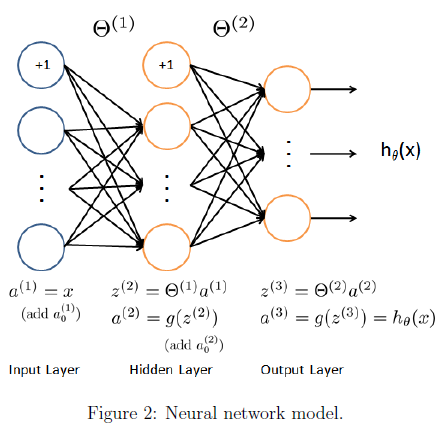

    You have been provided with a set of network parameters $(\Theta^{(1)},\Theta^{(2)})$ already trained by us. These are stored in `ex3weights.mat` and are loaded into `Theta1` and `Theta2 `by running the code below. The parameters have dimensions that are sized for a neural network with 25 units in the second layer and 10 output units (corresponding to the 10 digit classes).

load('ex3data1.mat');

Expected gradients:
 0.146561
 -0.548558
 0.724722
 1.398003

m = size(X, 1);

% Randomly select 100 data points to display
sel = randperm(size(X, 1));
sel = sel(1:100);
displayData(X(sel, :));

% Load saved matrices from file
load('ex3weights.mat'); 
% Theta1 has size 25 x 401
% Theta2 has size 10 x 26

### 2.2 Feedforward propagation and prediction

Now you will implement feedforward propagation for the neural network. You will need to complete the code in `predict.m` to return the neural network's prediction. You should implement the feedforward computation that computes $h_\theta(x^{(i)})$ for every example $i$ and returns the associated predictions. Similar to the one-vs-all classication strategy, the prediction from the neural network will be the label that has the largest output $(h_\theta(x))_k$.

**Implementation Note: **The matrix `X` contains the examples in rows. When you complete the code in `predict.m`, you will need to add the column of 1's to the matrix. The matrices `Theta1` and `Theta2` contain the parameters for each unit in rows. Specically, the first row of `Theta1` corresponds to the first hidden unit in the second layer. In MATLAB, when you compute $z^{(2)} = \Theta^{(1)}a^{(1)}$, be sure that you index (and if necessary, transpose) `X` correctly so that you get $a^{(1)}$ as a column vector.

Once you are done, run the code below to call your predict function using the loaded set of parameters for `Theta1` and `Theta2`. You should see that the accuracy is about 97.5%.

pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);

   0   0   1   0   0   0   0   0   0   0



The code below will displaying images from the training set one at a time, while the console prints out the predicted label for the displayed image. Rerun to repeat with another image.

%  Randomly permute examples
rp = randi(m);
% Predict
pred = predict(Theta1, Theta2, X(rp,:));

J = 0.6931

grad =     0.4000
         0
         0
   -0.0000
    0.0000
   -0.0000
    0.0001
    0.0001
    0.0000
    0.0000


J = 0.2802

grad =     0.0549
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


Iteration     1 | Cost: 2.802128e-01


J = 0.0945

grad =     0.0439
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000


Iteration     2 | Cost: 9.454389e-02


J = 1.2017

grad =    -0.1000
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


J = 0.0860

grad =    -0.0352
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


J = 0.0570

grad =    -0.0016
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


Iteration     3 | Cost: 5.704641e-02


J = 0.0839

grad =    -0.0038
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


J = 0.0469

grad =     0.0020
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


Iteration     4 | Cost: 4.688190e-02


J = 0.0376

grad =    -0.0053
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration     5 | Cost: 3.759021e-02


J = 0.0835

grad =     0.0330
         0
         0
   -0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0352

grad =     0.0031
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration     6 | Cost: 3.522008e-02


J = 0.0323

grad =     0.0004
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration     7 | Cost: 3.234531e-02


J = 0.0364

grad =     0.0104
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0315

grad =     0.0034
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration     8 | Cost: 3.145034e-02


J = 0.0301

grad =     0.0021
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration     9 | Cost: 3.008919e-02


J = 0.0345

grad =    -0.0067
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0299

grad = 	1.0e+-3 *

    0.8319
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0016
    0.0004
   -0.0001


Iteration    10 | Cost: 2.994639e-02


J = 0.0297

grad = 	1.0e+-3 *

    0.8364
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0016
    0.0004
   -0.0001


J = 0.0292

grad = 	1.0e+-3 *

    0.8505
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
    0.0017
    0.0004
   -0.0001


J = 0.0279

grad = 	1.0e+-3 *

    0.9426
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0002
    0.0019
    0.0005
   -0.0001


J = 0.0268

grad =     0.0015
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    11 | Cost: 2.678528e-02


J = 0.0828

grad =    -0.0414
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


J = 0.0267

grad =    -0.0014
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0266

grad =    -0.0003
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    12 | Cost: 2.660323e-02


J = 0.0263

grad =    -0.0001
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0257

grad = 	1.0e+-3 *

    0.2584
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0001
    0.0018
    0.0004
   -0.0001


J = 0.0249

grad =     0.0012
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    13 | Cost: 2.493301e-02


J = 0.0362

grad =    -0.0149
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


J = 0.0248

grad =    -0.0006
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration    14 | Cost: 2.475211e-02


J = 0.0244

grad =    -0.0004
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0239

grad = 	1.0e+-3 *

   -0.1670
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0001
    0.0009
   -0.0002
   -0.0000


J = 0.0232

grad =     0.0009
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000


Iteration    15 | Cost: 2.318421e-02


J = 0.0280

grad =    -0.0098
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


J = 0.0229

grad =    -0.0014
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000


Iteration    16 | Cost: 2.287050e-02


J = 0.0223

grad =    -0.0009
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000


J = 0.0216

grad = 	1.0e+-3 *

   -0.1131
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0000
    0.0001
   -0.0006
    0.0001


Iteration    17 | Cost: 2.160258e-02


J = 0.0220

grad =     0.0044
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0212

grad =     0.0018
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000


Iteration    18 | Cost: 2.120371e-02


J = 0.0206

grad = 	1.0e+-3 *

    0.4102
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0001
    0.0007
    0.0000
    0.0000


Iteration    19 | Cost: 2.064125e-02


J = 0.0221

grad =    -0.0041
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


J = 0.0206

grad = 	1.0e+-3 *

   -0.3167
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0001
    0.0005
   -0.0002
    0.0000


Iteration    20 | Cost: 2.055695e-02


J = 0.0205

grad = 	1.0e+-3 *

    0.3654
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0001
    0.0005
   -0.0002
    0.0000


Iteration    21 | Cost: 2.045466e-02


J = 0.0203

grad = 	1.0e+-3 *

   -0.2117
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0000
    0.0004
   -0.0003
    0.0000


J = 0.0203

grad = 	1.0e+-3 *

   -0.8712
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0000
    0.0003
   -0.0005
    0.0000


Iteration    22 | Cost: 2.029177e-02


J = 0.0201

grad = 	1.0e+-3 *

   -0.6246
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0000
    0.0004
   -0.0005
    0.0000


Iteration    23 | Cost: 2.005296e-02


J = 0.0200

grad =     0.0013
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0200

grad = 	1.0e+-3 *

    0.4674
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0001
    0.0006
   -0.0002
   -0.0000


Iteration    24 | Cost: 1.995949e-02


J = 0.0198

grad = 	1.0e+-3 *

    0.1290
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0001
    0.0007
   -0.0001
   -0.0000


Iteration    25 | Cost: 1.982849e-02


J = 0.0198

grad =    -0.0010
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration    26 | Cost: 1.975129e-02


J = 0.0196

grad = 	1.0e+-3 *

   -0.8593
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0001
    0.0006
   -0.0002
   -0.0000


J = 0.0193

grad = 401×1
	1.0e+-3 *

   -0.4864
         0
         0
   -0.0000
    0.0000
    0.0001
   -0.0001
    0.0007
   -0.0000
   -0.0000


J = 0.0190

grad = 401×1
	1.0e+-3 *

    0.5114
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0011
    0.0003
   -0.0000


Iteration    27 | Cost: 1.897815e-02


J = 0.0225

grad = 401×1
   -0.0063
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0189

grad = 401×1
	1.0e+-3 *

   -0.6496
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0010
    0.0002
   -0.0000


Iteration    28 | Cost: 1.887065e-02


J = 0.0187

grad = 401×1
	1.0e+-3 *

   -0.3741
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0013
    0.0005
   -0.0001


Iteration    29 | Cost: 1.869107e-02


J = 0.0187

grad = 401×1
    0.0014
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0186

grad = 401×1
	1.0e+-3 *

    0.4449
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0014
    0.0006
   -0.0001


Iteration    30 | Cost: 1.863223e-02


J = 0.0185

grad = 401×1
	1.0e+-3 *

    0.2880
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0013
    0.0005
   -0.0001


J = 0.0184

grad = 401×1
	1.0e+-3 *

   -0.0170
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0012
    0.0004
   -0.0001


Iteration    31 | Cost: 1.837393e-02


J = 0.0182

grad = 401×1
    0.0011
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    32 | Cost: 1.816950e-02


J = 0.0179

grad = 401×1
	1.0e+-3 *

    0.3755
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0009
    0.0003
   -0.0000


J = 0.0178

grad = 401×1
	1.0e+-3 *

   -0.3823
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0007
    0.0002
   -0.0000


Iteration    33 | Cost: 1.781689e-02


J = 0.0191

grad = 401×1
    0.0027
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000


J = 0.0177

grad = 401×1
	1.0e+-3 *

    0.0846
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0006
    0.0001
   -0.0000


Iteration    34 | Cost: 1.774664e-02


J = 0.0177

grad = 401×1
	1.0e+-3 *

    0.7072
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0006
    0.0002
   -0.0000


Iteration    35 | Cost: 1.767442e-02


J = 0.0176

grad = 401×1
	1.0e+-3 *

    0.1668
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0006
    0.0001
   -0.0000


Iteration    36 | Cost: 1.758469e-02


J = 0.0177

grad = 401×1
   -0.0013
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0176

grad = 401×1
	1.0e+-3 *

   -0.1922
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0006
    0.0001
   -0.0000


Iteration    37 | Cost: 1.756886e-02


J = 0.0175

grad = 401×1
	1.0e+-3 *

    0.0890
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0006
    0.0001
   -0.0000


J = 0.0175

grad = 401×1
	1.0e+-3 *

    0.4228
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0007
    0.0002
   -0.0000


Iteration    38 | Cost: 1.753427e-02


J = 0.0175

grad = 401×1
	1.0e+-3 *

    0.3319
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0007
    0.0002
   -0.0000


J = 0.0174

grad = 401×1
	1.0e+-3 *

    0.1461
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0008
    0.0003
   -0.0000


J = 0.0173

grad = 401×1
	1.0e+-3 *

   -0.2666
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0009
    0.0004
   -0.0000


Iteration    39 | Cost: 1.728312e-02


J = 0.0170

grad = 401×1
    0.0012
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    40 | Cost: 1.702085e-02


J = 0.0166

grad = 401×1
	1.0e+-3 *

    0.7231
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0012
    0.0005
   -0.0000


J = 0.0162

grad = 401×1
	1.0e+-3 *

   -0.2919
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0010
    0.0005
   -0.0000


Iteration    41 | Cost: 1.621402e-02


J = 0.0156

grad = 401×1
    0.0018
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    42 | Cost: 1.555312e-02


J = 0.0151

grad = 401×1
	1.0e+-3 *

   -0.5276
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
   -0.0000
   -0.0000


Iteration    43 | Cost: 1.507815e-02


J = 0.0149

grad = 401×1
	1.0e+-3 *

    0.0895
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0001
   -0.0000


J = 0.0147

grad = 401×1
	1.0e+-3 *

   -0.1212
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0001
   -0.0000


Iteration    44 | Cost: 1.467648e-02


J = 0.0146

grad = 401×1
   -0.0021
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0145

grad = 401×1
   -0.0012
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    45 | Cost: 1.445062e-02


J = 0.0142

grad = 401×1
	1.0e+-3 *

   -0.0062
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0006
    0.0003
   -0.0000


Iteration    46 | Cost: 1.424934e-02


J = 0.0140

grad = 401×1
	1.0e+-3 *

   -0.4728
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0006
    0.0004
   -0.0000


Iteration    47 | Cost: 1.401729e-02


J = 0.0141

grad = 401×1
    0.0017
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0139

grad = 401×1
	1.0e+-3 *

    0.3878
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0007
    0.0004
   -0.0000


Iteration    48 | Cost: 1.392951e-02


J = 0.0138

grad = 401×1
	1.0e+-3 *

    0.1091
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0006
    0.0004
   -0.0000


Iteration    49 | Cost: 1.381777e-02


J = 0.0137

grad = 401×1
	1.0e+-3 *

   -0.3407
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0005
    0.0003
   -0.0000


Iteration    50 | Cost: 1.372183e-02


J = 0.0140

grad = 401×1
    0.0015
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0137

grad = 401×1
	1.0e+-3 *

    0.0310
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0005
    0.0003
   -0.0000


Iteration    51 | Cost: 1.370350e-02


J = 0.0137

grad = 401×1
	1.0e+-3 *

   -0.0200
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0005
    0.0003
   -0.0000


J = 0.0137

grad = 401×1
	1.0e+-3 *

   -0.0886
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0004
    0.0003
   -0.0000


Iteration    52 | Cost: 1.365988e-02


J = 0.0136

grad = 401×1
	1.0e+-3 *

   -0.2854
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0004
    0.0003
   -0.0000


Iteration    53 | Cost: 1.360839e-02


J = 0.0137

grad = 401×1
	1.0e+-3 *

    0.9157
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0001
    0.0006
    0.0004
   -0.0000


J = 0.0136

grad = 401×1
	1.0e+-3 *

    0.0488
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0005
    0.0003
   -0.0000


Iteration    54 | Cost: 1.359620e-02


J = 0.0136

grad = 401×1
	1.0e+-3 *

    0.1106
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0005
    0.0003
   -0.0000


J = 0.0136

grad = 401×1
	1.0e+-3 *

    0.2354
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0005
    0.0003
   -0.0000


Iteration    55 | Cost: 1.355191e-02


J = 0.0136

grad = 401×1
	1.0e+-3 *

   -0.7462
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0135

grad = 401×1
	1.0e+-3 *

   -0.0917
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0004
    0.0003
   -0.0000


Iteration    56 | Cost: 1.353991e-02


J = 0.0135

grad = 401×1
	1.0e+-3 *

   -0.1063
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0004
    0.0002
   -0.0000


J = 0.0135

grad = 401×1
	1.0e+-3 *

   -0.1310
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


Iteration    57 | Cost: 1.350780e-02


J = 0.0137

grad = 401×1
    0.0014
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0135

grad = 401×1
	1.0e+-3 *

    0.0652
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


Iteration    58 | Cost: 1.350367e-02


J = 0.0135

grad = 401×1
	1.0e+-4 *

    0.5218
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0033
    0.0023
   -0.0001


J = 0.0135

grad = 401×1
	1.0e+-4 *

    0.2453
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0036
    0.0025
   -0.0001


Iteration    59 | Cost: 1.348958e-02


J = 0.0135

grad = 401×1
	1.0e+-3 *

   -0.2816
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


Iteration    60 | Cost: 1.347801e-02


J = 0.0135

grad = 401×1
	1.0e+-3 *

   -0.2278
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0135

grad = 401×1
	1.0e+-3 *

   -0.1697
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0004
    0.0002
   -0.0000


Iteration    61 | Cost: 1.345231e-02


J = 0.0135

grad = 401×1
	1.0e+-3 *

    0.7412
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0005
    0.0003
   -0.0000


J = 0.0134

grad = 401×1
	1.0e+-3 *

    0.0776
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0004
    0.0003
   -0.0000


Iteration    62 | Cost: 1.344543e-02


J = 0.0134

grad = 401×1
	1.0e+-4 *

    0.1937
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0004
    0.0039
    0.0025
   -0.0002


Iteration    63 | Cost: 1.343576e-02


J = 0.0134

grad = 401×1
	1.0e+-3 *

   -0.4509
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0134

grad = 401×1
	1.0e+-3 *

   -0.1042
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0004
    0.0002
   -0.0000


Iteration    64 | Cost: 1.343395e-02


J = 0.0134

grad = 401×1
	1.0e+-4 *

   -0.5765
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0036
    0.0023
   -0.0001


J = 0.0134

grad = 401×1
	1.0e+-4 *

    0.3541
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0035
    0.0023
   -0.0001


Iteration    65 | Cost: 1.342660e-02


J = 0.0134

grad = 401×1
	1.0e+-3 *

   -0.1797
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


Iteration    66 | Cost: 1.342241e-02


J = 0.0134

grad = 401×1
	1.0e+-3 *

   -0.3472
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0002
   -0.0000


J = 0.0134

grad = 401×1
	1.0e+-3 *

   -0.2277
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


Iteration    67 | Cost: 1.342091e-02


J = 0.0134

grad = 401×1
	1.0e+-3 *

   -0.1718
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0134

grad = 401×1
	1.0e+-4 *

   -0.5999
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0029
    0.0020
   -0.0001


Iteration    68 | Cost: 1.341496e-02


J = 0.0134

grad = 401×1
	1.0e+-3 *

    0.1400
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0134

grad = 401×1
	1.0e+-4 *

    0.4663
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0032
    0.0021
   -0.0001


Iteration    69 | Cost: 1.341251e-02


J = 0.0134

grad = 401×1
	1.0e+-3 *

   -0.1392
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0134

grad = 401×1
	1.0e+-4 *

   -0.4771
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0031
    0.0021
   -0.0001


Iteration    70 | Cost: 1.341127e-02


J = 0.0134

grad = 401×1
	1.0e+-4 *

   -0.1130
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0033
    0.0022
   -0.0001


J = 0.0134

grad = 401×1
	1.0e+-4 *

    0.2612
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0035
    0.0023
   -0.0001


Iteration    71 | Cost: 1.340876e-02


J = 0.0134

grad = 401×1
	1.0e+-3 *

   -0.1497
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0134

grad = 401×1
	1.0e+-4 *

   -0.7585
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0035
    0.0022
   -0.0001


Iteration    72 | Cost: 1.340730e-02


J = 0.0134

grad = 401×1
	1.0e+-4 *

   -0.4908
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0036
    0.0023
   -0.0001


J = 0.0134

grad = 401×1
	1.0e+-4 *

    0.0437
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0004
    0.0039
    0.0025
   -0.0002


Iteration    73 | Cost: 1.340167e-02


J = 0.0134

grad = 401×1
	1.0e+-4 *

   -0.1948
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0004
    0.0037
    0.0024
   -0.0002


J = 0.0134

grad = 401×1
	1.0e+-4 *

   -0.6708
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0035
    0.0022
   -0.0001


J = 0.0134

grad = 401×1
	1.0e+-3 *

   -0.2092
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


Iteration    74 | Cost: 1.336196e-02


J = 0.0135

grad = 401×1
	1.0e+-3 *

    0.9970
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0134

grad = 401×1
	1.0e+-3 *

    0.0419
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


Iteration    75 | Cost: 1.335388e-02


J = 0.0133

grad = 401×1
	1.0e+-3 *

    0.0417
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0133

grad = 401×1
	1.0e+-3 *

    0.0413
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0133

grad = 401×1
	1.0e+-3 *

    0.0412
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


Iteration    76 | Cost: 1.326557e-02


J = 0.0135

grad = 401×1
   -0.0015
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0133

grad = 401×1
	1.0e+-3 *

   -0.2677
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


Iteration    77 | Cost: 1.325044e-02


J = 0.0132

grad = 401×1
	1.0e+-3 *

   -0.1576
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


Iteration    78 | Cost: 1.322895e-02


J = 0.0133

grad = 401×1
	1.0e+-3 *

    0.8480
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.2820
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0021
    0.0012
   -0.0001


Iteration    79 | Cost: 1.322705e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.0667
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0022
    0.0013
   -0.0001


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.7728
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0024
    0.0014
   -0.0001


Iteration    80 | Cost: 1.322010e-02


J = 0.0132

grad = 401×1
	1.0e+-3 *

   -0.2984
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.4267
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0024
    0.0014
   -0.0001


Iteration    81 | Cost: 1.321827e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.6058
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0025
    0.0015
   -0.0001


Iteration    82 | Cost: 1.321562e-02


J = 0.0132

grad = 401×1
	1.0e+-3 *

    0.1039
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0003
    0.0002
   -0.0000


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.3988
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0027
    0.0016
   -0.0001


Iteration    83 | Cost: 1.321451e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.4769
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0026
    0.0016
   -0.0001


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.6332
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0003
    0.0026
    0.0015
   -0.0001


Iteration    84 | Cost: 1.320954e-02


J = 0.0132

grad = 401×1
	1.0e+-3 *

   -0.2449
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.3750
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0025
    0.0015
   -0.0001


Iteration    85 | Cost: 1.320845e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.6791
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0023
    0.0014
   -0.0001


J = 0.0132

grad = 401×1
	1.0e+-3 *

   -0.1288
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


Iteration    86 | Cost: 1.320514e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.2992
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0020
    0.0012
   -0.0001


Iteration    87 | Cost: 1.320224e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.3062
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0019
    0.0012
   -0.0001


Iteration    88 | Cost: 1.319774e-02


J = 0.0132

grad = 401×1
	1.0e+-3 *

   -0.2219
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.6973
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0019
    0.0012
   -0.0001


Iteration    89 | Cost: 1.319644e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.4196
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0021
    0.0013
   -0.0001


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.0392
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0023
    0.0015
   -0.0001


Iteration    90 | Cost: 1.319297e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.2819
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0023
    0.0014
   -0.0001


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.1573
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0023
    0.0014
   -0.0001


Iteration    91 | Cost: 1.319126e-02


J = 0.0132

grad = 401×1
	1.0e+-3 *

   -0.2123
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.5192
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0022
    0.0014
   -0.0001


Iteration    92 | Cost: 1.319076e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.4838
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0022
    0.0014
   -0.0001


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.4130
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0022
    0.0014
   -0.0001


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.2020
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0022
    0.0013
   -0.0001


Iteration    93 | Cost: 1.318571e-02


J = 0.0132

grad = 401×1
	1.0e+-3 *

    0.1707
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


Iteration    94 | Cost: 1.318183e-02


J = 0.0132

grad = 401×1
	1.0e+-3 *

    0.1389
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


Iteration    95 | Cost: 1.317576e-02


J = 0.0132

grad = 401×1
	1.0e+-3 *

   -0.1708
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.0314
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0021
    0.0013
   -0.0001


Iteration    96 | Cost: 1.317378e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.1676
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0021
    0.0013
   -0.0001


Iteration    97 | Cost: 1.317232e-02


J = 0.0132

grad = 401×1
	1.0e+-3 *

   -0.3344
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0002
    0.0001
   -0.0000


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.2941
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0020
    0.0013
   -0.0001


Iteration    98 | Cost: 1.317207e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.1659
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0020
    0.0012
   -0.0001


J = 0.0132

grad = 401×1
	1.0e+-4 *

    0.0907
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0020
    0.0012
   -0.0001


Iteration    99 | Cost: 1.317091e-02


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.8558
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0019
    0.0011
   -0.0001


J = 0.0132

grad = 401×1
	1.0e+-4 *

   -0.4396
         0
         0
   -0.0000
    0.0001
    0.0001
   -0.0002
    0.0019
    0.0012
   -0.0001


Iteration   100 | Cost: 1.317047e-02


all_theta = 10×401
   -3.0762         0         0    0.0001   -0.0010   -0.0011    0.0022   -0.0255   -0.0062    0.0009    0.0004    0.0000    0.0006    0.0029    0.0018    0.0027    0.0035    0.0003   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0013    0.0115    0.0131    0.0028   -0.0354   -0.0068    0.0039
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0        

J = 0.6931

grad = 401×1
    0.4000
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0001
    0.0001
    0.0000
    0.0000


J = 0.3449

grad = 401×1
    0.0432
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     1 | Cost: 3.448901e-01


J = 0.3151

grad = 401×1
    0.1476
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     2 | Cost: 3.150694e-01


J = 0.1847

grad = 401×1
   -0.0064
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000


Iteration     3 | Cost: 1.846843e-01


J = NaN

grad = 401×1
    0.2525
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000


J = NaN

grad = 401×1
    0.1514
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000


J = NaN

grad = 401×1
    0.0695
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000


J = 0.1849

grad = 401×1
    0.0261
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000


J = 0.1699

grad = 401×1
    0.0087
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000


Iteration     4 | Cost: 1.699017e-01


J = 0.1530

grad = 401×1
   -0.0072
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000


Iteration     5 | Cost: 1.529566e-01


J = 0.1317

grad = 401×1
    0.0034
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
   -0.0000


Iteration     6 | Cost: 1.317377e-01


J = 0.1172

grad = 401×1
   -0.0096
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


Iteration     7 | Cost: 1.171533e-01


J = 0.1137

grad = 401×1
    0.0123
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


J = 0.1074

grad = 401×1
	1.0e+00 *

    0.0010
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


Iteration     8 | Cost: 1.074286e-01


J = 0.0953

grad = 401×1
    0.0027
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


Iteration     9 | Cost: 9.531806e-02


J = 0.1086

grad = 401×1
   -0.0225
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


J = 0.0930

grad = 401×1
   -0.0057
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


Iteration    10 | Cost: 9.301912e-02


J = 0.0886

grad = 401×1
   -0.0064
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000


J = 0.0842

grad = 401×1
   -0.0068
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


Iteration    11 | Cost: 8.418356e-02


J = 0.0981

grad = 401×1
    0.0277
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000


J = 0.0819

grad = 401×1
	1.0e+00 *

    0.0002
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


Iteration    12 | Cost: 8.186322e-02


J = 0.0787

grad = 401×1
	1.0e+00 *

    0.0005
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


J = 0.0774

grad = 401×1
    0.0014
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


Iteration    13 | Cost: 7.743126e-02


J = 0.0878

grad = 401×1
   -0.0204
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


J = 0.0765

grad = 401×1
   -0.0039
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


Iteration    14 | Cost: 7.645181e-02


J = 0.0746

grad = 401×1
   -0.0031
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
    0.0000


J = 0.0721

grad = 401×1
   -0.0011
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    15 | Cost: 7.209877e-02


J = 0.1484

grad = 401×1
    0.0687
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0721

grad = 401×1
    0.0035
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0720

grad = 401×1
    0.0010
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    16 | Cost: 7.195896e-02


J = 0.0717

grad = 401×1
	1.0e+00 *

    0.0006
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0713

grad = 401×1
	1.0e+00 *

   -0.0003
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0711

grad = 401×1
   -0.0016
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    17 | Cost: 7.106302e-02


J = 0.0729

grad = 401×1
    0.0093
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0708

grad = 401×1
	1.0e+00 *

    0.0009
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    18 | Cost: 7.081516e-02


J = 0.0704

grad = 401×1
	1.0e+-3 *

    0.7862
         0
         0
    0.0000
   -0.0001
    0.0003
    0.0036
    0.0013
    0.0022
    0.0001


J = 0.0698

grad = 401×1
	1.0e+00 *

    0.0007
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    19 | Cost: 6.984782e-02


J = 0.0691

grad = 401×1
   -0.0028
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    20 | Cost: 6.908892e-02


J = 0.0682

grad = 401×1
	1.0e+00 *

   -0.0002
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    21 | Cost: 6.818820e-02


J = 0.0703

grad = 401×1
    0.0095
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0680

grad = 401×1
    0.0016
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    22 | Cost: 6.804182e-02


J = 0.0679

grad = 401×1
	1.0e+-3 *

    0.0521
         0
         0
    0.0000
   -0.0001
    0.0002
    0.0034
    0.0014
    0.0021
    0.0002


Iteration    23 | Cost: 6.788125e-02


J = 0.0678

grad = 401×1
    0.0023
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0678

grad = 401×1
    0.0014
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    24 | Cost: 6.779397e-02


J = 0.0677

grad = 401×1
	1.0e+-3 *

    0.8455
         0
         0
    0.0000
   -0.0001
    0.0002
    0.0033
    0.0012
    0.0018
    0.0002


Iteration    25 | Cost: 6.767277e-02


J = 0.0676

grad = 401×1
	1.0e+00 *

   -0.0009
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    26 | Cost: 6.760372e-02


J = 0.0675

grad = 401×1
	1.0e+-3 *

   -0.7156
         0
         0
    0.0000
   -0.0001
    0.0002
    0.0034
    0.0016
    0.0024
    0.0002


J = 0.0674

grad = 401×1
	1.0e+-3 *

   -0.4049
         0
         0
    0.0000
   -0.0001
    0.0002
    0.0035
    0.0019
    0.0030
    0.0002


Iteration    27 | Cost: 6.740638e-02


J = 0.0674

grad = 401×1
    0.0036
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0673

grad = 401×1
    0.0014
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    28 | Cost: 6.731728e-02


J = 0.0672

grad = 401×1
    0.0012
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0670

grad = 401×1
	1.0e+-3 *

    0.8191
         0
         0
    0.0000
   -0.0001
    0.0002
    0.0033
    0.0013
    0.0020
    0.0002


Iteration    29 | Cost: 6.698888e-02


J = 0.0676

grad = 401×1
   -0.0054
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0669

grad = 401×1
	1.0e+-3 *

   -0.6760
         0
         0
    0.0000
   -0.0001
    0.0002
    0.0033
    0.0014
    0.0020
    0.0002


Iteration    30 | Cost: 6.692984e-02


J = 0.0668

grad = 401×1
	1.0e+-3 *

   -0.7411
         0
         0
    0.0000
   -0.0001
    0.0002
    0.0034
    0.0015
    0.0022
    0.0002


J = 0.0666

grad = 401×1
	1.0e+-3 *

   -0.8517
         0
         0
    0.0000
   -0.0001
    0.0002
    0.0034
    0.0017
    0.0026
    0.0002


J = 0.0663

grad = 401×1
   -0.0010
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    31 | Cost: 6.630404e-02


J = 0.0665

grad = 401×1
    0.0062
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0661

grad = 401×1
    0.0019
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    32 | Cost: 6.606809e-02


J = 0.0656

grad = 401×1
    0.0020
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0650

grad = 401×1
    0.0024
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0647

grad = 401×1
    0.0033
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    33 | Cost: 6.466816e-02


J = 0.0665

grad = 401×1
   -0.0091
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0643

grad = 401×1
	1.0e+00 *

   -0.0008
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    34 | Cost: 6.426962e-02


J = 0.0635

grad = 401×1
   -0.0011
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0627

grad = 401×1
   -0.0015
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    35 | Cost: 6.267791e-02


J = 0.0709

grad = 401×1
    0.0208
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0625

grad = 401×1
	1.0e+-3 *

    0.7112
         0
         0
    0.0000
   -0.0001
    0.0001
    0.0028
    0.0022
    0.0033
    0.0003


Iteration    36 | Cost: 6.251576e-02


J = 0.0623

grad = 401×1
	1.0e+-3 *

    0.9183
         0
         0
    0.0000
   -0.0001
    0.0001
    0.0026
    0.0020
    0.0029
    0.0003


J = 0.0620

grad = 401×1
    0.0015
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    37 | Cost: 6.202834e-02


J = 0.0625

grad = 401×1
   -0.0051
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0619

grad = 401×1
	1.0e+00 *

   -0.0009
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    38 | Cost: 6.188521e-02


J = 0.0616

grad = 401×1
   -0.0013
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0611

grad = 401×1
   -0.0020
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0601

grad = 401×1
   -0.0039
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    39 | Cost: 6.013896e-02


J = 0.0594

grad = 401×1
    0.0037
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    40 | Cost: 5.937078e-02


J = 0.0603

grad = 401×1
   -0.0069
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0589

grad = 401×1
	1.0e+-3 *

   -0.4772
         0
         0
    0.0000
   -0.0001
    0.0001
    0.0012
    0.0017
    0.0033
    0.0002


Iteration    41 | Cost: 5.888593e-02


J = 0.0589

grad = 401×1
	1.0e+-3 *

    0.1434
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0013
    0.0008
    0.0011
    0.0002


J = 0.0586

grad = 401×1
	1.0e+-3 *

   -0.2794
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0012
    0.0012
    0.0021
    0.0002


Iteration    42 | Cost: 5.862828e-02


J = 0.0589

grad = 401×1
    0.0037
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0585

grad = 401×1
	1.0e+-3 *

    0.8370
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0013
    0.0013
    0.0023
    0.0002


Iteration    43 | Cost: 5.854428e-02


J = 0.0585

grad = 401×1
	1.0e+-3 *

   -0.4506
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0014
    0.0014
    0.0024
    0.0002


Iteration    44 | Cost: 5.847598e-02


J = 0.0584

grad = 401×1
	1.0e+-3 *

    0.1048
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0014
    0.0015
    0.0026
    0.0002


Iteration    45 | Cost: 5.840091e-02


J = 0.0583

grad = 401×1
	1.0e+-3 *

   -0.3486
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0014
    0.0015
    0.0024
    0.0003


J = 0.0581

grad = 401×1
   -0.0012
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    46 | Cost: 5.812346e-02


J = 0.0583

grad = 401×1
    0.0032
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0580

grad = 401×1
	1.0e+-3 *

    0.3796
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0013
    0.0013
    0.0020
    0.0003


Iteration    47 | Cost: 5.803255e-02


J = 0.0579

grad = 401×1
	1.0e+-3 *

    0.4883
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0013
    0.0014
    0.0021
    0.0003


J = 0.0577

grad = 401×1
	1.0e+-3 *

    0.7840
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0012
    0.0014
    0.0022
    0.0004


Iteration    48 | Cost: 5.773509e-02


J = 0.0579

grad = 401×1
   -0.0036
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0576

grad = 401×1
   -0.0010
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    49 | Cost: 5.763070e-02


J = 0.0574

grad = 401×1
	1.0e+-3 *

   -0.8159
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0017
    0.0028
    0.0003


J = 0.0573

grad = 401×1
	1.0e+-3 *

   -0.3400
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0021
    0.0038
    0.0003


Iteration    50 | Cost: 5.725247e-02


J = 0.0591

grad = 401×1
    0.0090
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0572

grad = 401×1
	1.0e+-3 *

    0.7628
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0021
    0.0038
    0.0003


Iteration    51 | Cost: 5.721067e-02


J = 0.0571

grad = 401×1
	1.0e+-3 *

    0.5645
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0019
    0.0034
    0.0003


J = 0.0571

grad = 401×1
	1.0e+-3 *

    0.1974
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0016
    0.0028
    0.0003


Iteration    52 | Cost: 5.705079e-02


J = 0.0572

grad = 401×1
   -0.0027
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0570

grad = 401×1
	1.0e+-3 *

   -0.7010
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0016
    0.0028
    0.0002


Iteration    53 | Cost: 5.701652e-02


J = 0.0570

grad = 401×1
	1.0e+-3 *

   -0.2202
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0017
    0.0030
    0.0002


Iteration    54 | Cost: 5.696308e-02


J = 0.0570

grad = 401×1
    0.0018
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0570

grad = 401×1
	1.0e+-3 *

    0.2608
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0017
    0.0029
    0.0002


Iteration    55 | Cost: 5.695415e-02


J = 0.0569

grad = 401×1
	1.0e+-3 *

    0.0539
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0016
    0.0028
    0.0002


J = 0.0569

grad = 401×1
	1.0e+-3 *

   -0.3504
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0015
    0.0026
    0.0002


Iteration    56 | Cost: 5.692669e-02


J = 0.0569

grad = 401×1
	1.0e+-3 *

    0.4977
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0011
    0.0014
    0.0024
    0.0002


Iteration    57 | Cost: 5.690887e-02


J = 0.0569

grad = 401×1
	1.0e+-3 *

    0.5973
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0011
    0.0012
    0.0019
    0.0002


Iteration    58 | Cost: 5.689454e-02


J = 0.0569

grad = 401×1
	1.0e+-3 *

   -0.0765
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0011
    0.0012
    0.0019
    0.0002


Iteration    59 | Cost: 5.685578e-02


J = 0.0568

grad = 401×1
	1.0e+-3 *

   -0.0226
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0011
    0.0012
    0.0020
    0.0002


J = 0.0567

grad = 401×1
	1.0e+-3 *

    0.1063
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0012
    0.0014
    0.0023
    0.0002


Iteration    60 | Cost: 5.674870e-02


J = 0.0572

grad = 401×1
   -0.0039
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0567

grad = 401×1
	1.0e+-3 *

   -0.4693
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0012
    0.0014
    0.0023
    0.0002


Iteration    61 | Cost: 5.673793e-02


J = 0.0567

grad = 401×1
	1.0e+-3 *

   -0.2274
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0012
    0.0014
    0.0024
    0.0002


J = 0.0567

grad = 401×1
	1.0e+-3 *

    0.2631
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0015
    0.0026
    0.0002


Iteration    62 | Cost: 5.669404e-02


J = 0.0567

grad = 401×1
	1.0e+-3 *

   -0.6030
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0015
    0.0026
    0.0002


Iteration    63 | Cost: 5.665658e-02


J = 0.0566

grad = 401×1
	1.0e+-3 *

   -0.7460
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0016
    0.0027
    0.0002


J = 0.0565

grad = 401×1
   -0.0010
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    64 | Cost: 5.653233e-02


J = 0.0564

grad = 401×1
	1.0e+-3 *

    0.5790
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0017
    0.0031
    0.0002


Iteration    65 | Cost: 5.641219e-02


J = 0.0562

grad = 401×1
	1.0e+-3 *

    0.4987
         0
         0
    0.0000
   -0.0001
    0.0000
    0.0012
    0.0016
    0.0028
    0.0002


J = 0.0560

grad = 401×1
	1.0e+-3 *

    0.3918
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0011
    0.0013
    0.0022
    0.0002


J = 0.0558

grad = 401×1
	1.0e+-3 *

    0.3676
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0010
    0.0009
    0.0014
    0.0002


Iteration    66 | Cost: 5.577523e-02


J = 0.0591

grad = 401×1
   -0.0108
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0557

grad = 401×1
   -0.0014
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    67 | Cost: 5.569068e-02


J = 0.0555

grad = 401×1
   -0.0014
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0552

grad = 401×1
   -0.0015
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0546

grad = 401×1
   -0.0015
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    68 | Cost: 5.460414e-02


J = 0.0619

grad = 401×1
    0.0172
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0545

grad = 401×1
	1.0e+-3 *

    0.1428
         0
         0
    0.0000
   -0.0000
    0.0001
    0.0010
    0.0010
    0.0014
    0.0001


Iteration    69 | Cost: 5.452107e-02


J = 0.0544

grad = 401×1
	1.0e+-3 *

    0.2568
         0
         0
    0.0000
   -0.0000
    0.0001
    0.0010
    0.0009
    0.0014
    0.0001


J = 0.0543

grad = 401×1
	1.0e+-3 *

    0.5217
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0009
    0.0008
    0.0012
    0.0001


Iteration    70 | Cost: 5.426666e-02


J = 0.0550

grad = 401×1
   -0.0053
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0542

grad = 401×1
	1.0e+-3 *

   -0.7241
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0009
    0.0008
    0.0012
    0.0001


Iteration    71 | Cost: 5.421761e-02


J = 0.0541

grad = 401×1
	1.0e+-3 *

   -0.6989
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0009
    0.0009
    0.0013
    0.0001


J = 0.0540

grad = 401×1
	1.0e+-3 *

   -0.6360
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0010
    0.0015
    0.0001


J = 0.0538

grad = 401×1
	1.0e+-3 *

   -0.4285
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0012
    0.0021
    0.0001


Iteration    72 | Cost: 5.383450e-02


J = 0.0603

grad = 401×1
    0.0156
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0538

grad = 401×1
	1.0e+-3 *

    0.9733
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0012
    0.0022
    0.0001


J = 0.0538

grad = 401×1
	1.0e+-3 *

    0.3779
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0012
    0.0022
    0.0001


Iteration    73 | Cost: 5.381229e-02


J = 0.0538

grad = 401×1
	1.0e+-3 *

    0.2290
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0011
    0.0020
    0.0001


J = 0.0538

grad = 401×1
	1.0e+-3 *

   -0.0025
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0010
    0.0017
    0.0001


Iteration    74 | Cost: 5.375287e-02


J = 0.0538

grad = 401×1
   -0.0017
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0537

grad = 401×1
	1.0e+-3 *

   -0.8003
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0010
    0.0017
    0.0001


Iteration    75 | Cost: 5.372528e-02


J = 0.0537

grad = 401×1
	1.0e+-3 *

   -0.4912
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0010
    0.0017
    0.0001


J = 0.0536

grad = 401×1
	1.0e+-3 *

    0.0621
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0011
    0.0019
    0.0001


Iteration    76 | Cost: 5.364883e-02


J = 0.0536

grad = 401×1
	1.0e+-3 *

    0.3394
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0010
    0.0016
    0.0001


Iteration    77 | Cost: 5.356486e-02


J = 0.0539

grad = 401×1
   -0.0035
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0536

grad = 401×1
	1.0e+-3 *

   -0.2566
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0009
    0.0010
    0.0016
    0.0001


Iteration    78 | Cost: 5.355386e-02


J = 0.0535

grad = 401×1
	1.0e+-3 *

   -0.3266
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0009
    0.0010
    0.0016
    0.0001


J = 0.0535

grad = 401×1
	1.0e+-3 *

   -0.4630
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0009
    0.0010
    0.0016
    0.0001


J = 0.0535

grad = 401×1
	1.0e+-3 *

   -0.8428
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0009
    0.0011
    0.0018
    0.0001


Iteration    79 | Cost: 5.345397e-02


J = 0.0536

grad = 401×1
    0.0022
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0534

grad = 401×1
	1.0e+-3 *

    0.0974
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0011
    0.0019
    0.0001


Iteration    80 | Cost: 5.342199e-02


J = 0.0534

grad = 401×1
	1.0e+-3 *

    0.1279
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0011
    0.0018
    0.0001


J = 0.0533

grad = 401×1
	1.0e+-3 *

    0.2016
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0010
    0.0017
    0.0001


Iteration    81 | Cost: 5.329792e-02


J = 0.0535

grad = 401×1
   -0.0030
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0533

grad = 401×1
	1.0e+-3 *

   -0.6186
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0010
    0.0016
    0.0001


Iteration    82 | Cost: 5.327445e-02


J = 0.0532

grad = 401×1
	1.0e+-3 *

   -0.7227
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0010
    0.0017
    0.0001


J = 0.0532

grad = 401×1
	1.0e+-3 *

   -0.9189
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0011
    0.0018
    0.0001


Iteration    83 | Cost: 5.318457e-02


J = 0.0532

grad = 401×1
	1.0e+-3 *

    0.9729
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0006
    0.0011
    0.0020
    0.0001


J = 0.0531

grad = 401×1
	1.0e+-3 *

    0.2140
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0011
    0.0020
    0.0001


Iteration    84 | Cost: 5.314113e-02


J = 0.0531

grad = 401×1
	1.0e+-3 *

    0.4143
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0006
    0.0010
    0.0017
    0.0001


J = 0.0531

grad = 401×1
	1.0e+-3 *

    0.6411
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0006
    0.0009
    0.0015
    0.0001


Iteration    85 | Cost: 5.305332e-02


J = 0.0532

grad = 401×1
   -0.0022
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0530

grad = 401×1
	1.0e+-3 *

   -0.2199
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0006
    0.0008
    0.0014
    0.0001


Iteration    86 | Cost: 5.302760e-02


J = 0.0530

grad = 401×1
	1.0e+-3 *

   -0.2270
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0006
    0.0009
    0.0015
    0.0001


J = 0.0529

grad = 401×1
	1.0e+-3 *

   -0.2263
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0006
    0.0010
    0.0017
    0.0001


Iteration    87 | Cost: 5.291766e-02


J = 0.0538

grad = 401×1
    0.0056
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0529

grad = 401×1
	1.0e+-3 *

    0.3263
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0006
    0.0010
    0.0017
    0.0001


Iteration    88 | Cost: 5.291195e-02


J = 0.0529

grad = 401×1
	1.0e+-3 *

    0.7993
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0006
    0.0010
    0.0018
    0.0001


Iteration    89 | Cost: 5.290621e-02


J = 0.0529

grad = 401×1
	1.0e+-3 *

    0.6276
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0006
    0.0010
    0.0018
    0.0001


J = 0.0529

grad = 401×1
	1.0e+-3 *

    0.2866
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0006
    0.0010
    0.0018
    0.0001


J = 0.0529

grad = 401×1
	1.0e+-3 *

   -0.2656
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0010
    0.0018
    0.0001


Iteration    90 | Cost: 5.285744e-02


J = 0.0528

grad = 401×1
	1.0e+-3 *

    0.7826
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0011
    0.0019
    0.0001


J = 0.0528

grad = 401×1
	1.0e+-3 *

    0.3172
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0010
    0.0018
    0.0001


Iteration    91 | Cost: 5.282992e-02


J = 0.0528

grad = 401×1
	1.0e+-3 *

   -0.3723
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0010
    0.0017
    0.0001


Iteration    92 | Cost: 5.280240e-02


J = 0.0528

grad = 401×1
	1.0e+-3 *

    0.0995
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0010
    0.0017
    0.0001


Iteration    93 | Cost: 5.276609e-02


J = 0.0527

grad = 401×1
	1.0e+-3 *

   -0.4092
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0010
    0.0016
    0.0000


Iteration    94 | Cost: 5.272582e-02


J = 0.0527

grad = 401×1
	1.0e+-3 *

    0.2449
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0010
    0.0017
    0.0001


Iteration    95 | Cost: 5.268934e-02


J = 0.0526

grad = 401×1
	1.0e+-3 *

   -0.0915
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0010
    0.0016
    0.0001


Iteration    96 | Cost: 5.264834e-02


J = 0.0526

grad = 401×1
	1.0e+-3 *

    0.5532
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0010
    0.0017
    0.0001


Iteration    97 | Cost: 5.261758e-02


J = 0.0526

grad = 401×1
	1.0e+-3 *

    0.0975
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0010
    0.0016
    0.0001


Iteration    98 | Cost: 5.258979e-02


J = 0.0526

grad = 401×1
   -0.0010
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0526

grad = 401×1
	1.0e+-3 *

   -0.3985
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0008
    0.0009
    0.0015
    0.0001


Iteration    99 | Cost: 5.257766e-02


J = 0.0526

grad = 401×1
	1.0e+-3 *

   -0.0756
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0007
    0.0009
    0.0015
    0.0001


Iteration   100 | Cost: 5.256287e-02


all_theta = 10×401
   -3.0762         0         0    0.0001   -0.0010   -0.0011    0.0022   -0.0255   -0.0062    0.0009    0.0004    0.0000    0.0006    0.0029    0.0018    0.0027    0.0035    0.0003   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0013    0.0115    0.0131    0.0028   -0.0354   -0.0068    0.0039
   -3.5421         0         0   -0.0001    0.0008   -0.0013   -0.0268   -0.0224   -0.0359   -0.0033   -0.0234   -0.0086    0.0071    0.0084    0.0022   -0.0266   -0.0140    0.0089   -0.0003   -0.0000         0   -0.0000   -0.0000    0.0015   -0.0086    0.0243    0.2703   -0.1338   -0.2848   -0.0611
         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0        

J = 0.6931

grad = 401×1
    0.4000
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0001
    0.0000
    0.0000


J = 0.3457

grad = 401×1
    0.0432
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration     1 | Cost: 3.456557e-01


J = 0.4052

grad = 401×1
    0.1569
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.2179

grad = 401×1
    0.1031
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration     2 | Cost: 2.179164e-01


J = 0.1784

grad = 401×1
   -0.0367
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration     3 | Cost: 1.784174e-01


J = NaN

grad = 401×1
    0.0269
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.2436

grad = 401×1
    0.0133
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.1679

grad = 401×1
   -0.0076
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration     4 | Cost: 1.678808e-01


J = 0.1489

grad = 401×1
    0.0380
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.1427

grad = 401×1
    0.0196
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration     5 | Cost: 1.427129e-01


J = 0.1150

grad = 401×1
    0.0268
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration     6 | Cost: 1.150393e-01


J = 0.1233

grad = 401×1
   -0.0242
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.1064

grad = 401×1
    0.0029
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration     7 | Cost: 1.063718e-01


J = 0.0971

grad = 401×1
    0.0049
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration     8 | Cost: 9.707803e-02


J = 0.1283

grad = 401×1
    0.0567
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0952

grad = 401×1
    0.0129
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     9 | Cost: 9.518367e-02


J = 0.0924

grad = 401×1
    0.0081
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0904

grad = 401×1
	1.0e+00 *

    0.0002
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    10 | Cost: 9.035733e-02


J = 0.1062

grad = 401×1
    0.0300
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0893

grad = 401×1
    0.0053
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    11 | Cost: 8.928846e-02


J = 0.0875

grad = 401×1
    0.0029
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0853

grad = 401×1
   -0.0012
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    12 | Cost: 8.531186e-02


J = 0.0840

grad = 401×1
    0.0131
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0833

grad = 401×1
    0.0078
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    13 | Cost: 8.333526e-02


J = 0.0805

grad = 401×1
    0.0086
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    14 | Cost: 8.052683e-02


J = 0.0798

grad = 401×1
   -0.0035
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0793

grad = 401×1
	1.0e+00 *

    0.0009
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    15 | Cost: 7.932857e-02


J = 0.0775

grad = 401×1
	1.0e+00 *

    0.0009
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0767

grad = 401×1
    0.0016
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    16 | Cost: 7.672637e-02


J = 0.0753

grad = 401×1
    0.0062
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    17 | Cost: 7.530942e-02


J = 0.0882

grad = 401×1
   -0.0136
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0750

grad = 401×1
    0.0026
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    18 | Cost: 7.500108e-02


J = 0.0745

grad = 401×1
	1.0e+00 *

    0.0004
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    19 | Cost: 7.445295e-02


J = 0.0739

grad = 401×1
    0.0027
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    20 | Cost: 7.391453e-02


J = 0.0735

grad = 401×1
	1.0e+00 *

   -0.0004
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    21 | Cost: 7.349869e-02


J = 0.0731

grad = 401×1
	1.0e+00 *

    0.0008
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    22 | Cost: 7.307295e-02


J = 0.0737

grad = 401×1
    0.0079
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0730

grad = 401×1
    0.0026
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    23 | Cost: 7.296937e-02


J = 0.0728

grad = 401×1
    0.0020
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0726

grad = 401×1
    0.0010
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    24 | Cost: 7.262398e-02


J = 0.0721

grad = 401×1
    0.0012
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0713

grad = 401×1
    0.0016
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    25 | Cost: 7.129794e-02


J = 0.0763

grad = 401×1
   -0.0147
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0712

grad = 401×1
	1.0e+00 *

   -0.0008
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    26 | Cost: 7.118480e-02


J = 0.0710

grad = 401×1
   -0.0021
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0709

grad = 401×1
   -0.0039
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


Iteration    27 | Cost: 7.089717e-02


J = 0.0704

grad = 401×1
   -0.0030
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.0696

grad = 401×1
   -0.0012
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    28 | Cost: 6.963444e-02


J = 0.0961

grad = 401×1
    0.0384
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0697

grad = 401×1
    0.0016
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0696

grad = 401×1
	1.0e+00 *

   -0.0001
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    29 | Cost: 6.959800e-02


J = 0.0695

grad = 401×1
	1.0e+00 *

    0.0002
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0694

grad = 401×1
	1.0e+-3 *

    0.6537
         0
         0
    0.0000
    0.0000
   -0.0008
   -0.0041
    0.0039
    0.0011
   -0.0000


J = 0.0692

grad = 401×1
    0.0021
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    30 | Cost: 6.916222e-02


J = 0.0689

grad = 401×1
   -0.0014
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    31 | Cost: 6.893779e-02


J = 0.0734

grad = 401×1
   -0.0060
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0689

grad = 401×1
   -0.0020
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0689

grad = 401×1
   -0.0018
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    32 | Cost: 6.891918e-02


J = 0.0689

grad = 401×1
   -0.0015
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0688

grad = 401×1
	1.0e+00 *

   -0.0010
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0687

grad = 401×1
	1.0e+-3 *

    0.6458
         0
         0
    0.0000
    0.0000
   -0.0008
   -0.0040
    0.0040
    0.0009
   -0.0001


Iteration    33 | Cost: 6.872557e-02


J = 0.0685

grad = 401×1
	1.0e+-3 *

    0.5722
         0
         0
    0.0000
    0.0000
   -0.0008
   -0.0041
    0.0039
    0.0010
   -0.0001


Iteration    34 | Cost: 6.853783e-02


J = 0.0689

grad = 401×1
   -0.0046
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0685

grad = 401×1
	1.0e+-3 *

   -0.6943
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0044
    0.0038
    0.0009
   -0.0001


Iteration    35 | Cost: 6.849913e-02


J = 0.0684

grad = 401×1
	1.0e+-3 *

   -0.7927
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0043
    0.0039
    0.0009
   -0.0001


J = 0.0683

grad = 401×1
	1.0e+00 *

   -0.0010
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0679

grad = 401×1
   -0.0015
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0675

grad = 401×1
   -0.0028
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    36 | Cost: 6.754746e-02


J = 0.0681

grad = 401×1
    0.0067
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0672

grad = 401×1
	1.0e+00 *

    0.0008
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    37 | Cost: 6.715123e-02


J = 0.0665

grad = 401×1
	1.0e+-3 *

    0.8565
         0
         0
    0.0000
    0.0000
   -0.0008
   -0.0007
    0.0068
    0.0003
   -0.0010


J = 0.0658

grad = 401×1
    0.0011
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    38 | Cost: 6.581375e-02


J = 0.0769

grad = 401×1
   -0.0189
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0657

grad = 401×1
   -0.0012
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    39 | Cost: 6.572620e-02


J = 0.0656

grad = 401×1
   -0.0024
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    40 | Cost: 6.555641e-02


J = 0.0654

grad = 401×1
   -0.0013
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0652

grad = 401×1
	1.0e+-3 *

    0.8464
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0028
    0.0055
    0.0004
   -0.0008


Iteration    41 | Cost: 6.515479e-02


J = 0.0646

grad = 401×1
	1.0e+-3 *

    0.0740
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0034
    0.0053
    0.0002
   -0.0008


Iteration    42 | Cost: 6.464687e-02


J = 0.0646

grad = 401×1
    0.0028
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0644

grad = 401×1
    0.0015
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    43 | Cost: 6.444685e-02


J = 0.0645

grad = 401×1
	1.0e+00 *

   -0.0007
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0644

grad = 401×1
	1.0e+-3 *

    0.3951
         0
         0
    0.0000
    0.0001
   -0.0010
   -0.0042
    0.0054
    0.0003
   -0.0009


Iteration    44 | Cost: 6.435038e-02


J = 0.0644

grad = 401×1
   -0.0019
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0643

grad = 401×1
	1.0e+-3 *

   -0.5571
         0
         0
    0.0000
    0.0001
   -0.0010
   -0.0045
    0.0052
    0.0003
   -0.0008


Iteration    45 | Cost: 6.431183e-02


J = 0.0643

grad = 401×1
	1.0e+-3 *

    0.1782
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0040
    0.0051
    0.0002
   -0.0008


Iteration    46 | Cost: 6.427368e-02


J = 0.0643

grad = 401×1
   -0.0016
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0643

grad = 401×1
	1.0e+-3 *

   -0.2959
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0042
    0.0050
    0.0002
   -0.0008


Iteration    47 | Cost: 6.426368e-02


J = 0.0642

grad = 401×1
	1.0e+-3 *

   -0.0330
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0040
    0.0049
    0.0002
   -0.0008


J = 0.0642

grad = 401×1
	1.0e+-3 *

    0.3056
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0039
    0.0048
    0.0002
   -0.0008


Iteration    48 | Cost: 6.424060e-02


J = 0.0642

grad = 401×1
	1.0e+-3 *

   -0.2328
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0041
    0.0046
    0.0002
   -0.0007


Iteration    49 | Cost: 6.420980e-02


J = 0.0642

grad = 401×1
	1.0e+-3 *

    0.2503
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0039
    0.0046
    0.0002
   -0.0007


J = 0.0641

grad = 401×1
    0.0011
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    50 | Cost: 6.414641e-02


J = 0.0641

grad = 401×1
    0.0011
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    51 | Cost: 6.405443e-02


J = 0.0640

grad = 401×1
	1.0e+-3 *

   -0.8665
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0044
    0.0041
    0.0002
   -0.0007


J = 0.0640

grad = 401×1
	1.0e+-3 *

   -0.0955
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0041
    0.0042
    0.0002
   -0.0007


Iteration    52 | Cost: 6.401658e-02


J = 0.0640

grad = 401×1
	1.0e+-3 *

   -0.0838
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0041
    0.0045
    0.0002
   -0.0008


J = 0.0639

grad = 401×1
	1.0e+-3 *

   -0.0358
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0039
    0.0050
    0.0001
   -0.0009


Iteration    53 | Cost: 6.388445e-02


J = 0.0642

grad = 401×1
    0.0042
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0639

grad = 401×1
	1.0e+-3 *

    0.8235
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0037
    0.0052
    0.0001
   -0.0009


Iteration    54 | Cost: 6.385997e-02


J = 0.0638

grad = 401×1
	1.0e+-3 *

    0.7362
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0039
    0.0051
    0.0002
   -0.0009


J = 0.0638

grad = 401×1
	1.0e+-3 *

    0.5719
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0043
    0.0049
    0.0003
   -0.0008


Iteration    55 | Cost: 6.375589e-02


J = 0.0642

grad = 401×1
   -0.0039
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0637

grad = 401×1
	1.0e+-3 *

    0.0059
         0
         0
    0.0000
    0.0001
   -0.0010
   -0.0045
    0.0048
    0.0003
   -0.0008


Iteration    56 | Cost: 6.374731e-02


J = 0.0637

grad = 401×1
	1.0e+-3 *

    0.0550
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0044
    0.0049
    0.0002
   -0.0008


J = 0.0637

grad = 401×1
	1.0e+-3 *

    0.1558
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0042
    0.0050
    0.0002
   -0.0009


J = 0.0637

grad = 401×1
	1.0e+-3 *

    0.4273
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0036
    0.0053
    0.0001
   -0.0010


Iteration    57 | Cost: 6.367630e-02


J = 0.0639

grad = 401×1
   -0.0028
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0637

grad = 401×1
	1.0e+-3 *

   -0.3122
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0038
    0.0052
    0.0001
   -0.0010


Iteration    58 | Cost: 6.366068e-02


J = 0.0636

grad = 401×1
	1.0e+-3 *

   -0.3073
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0038
    0.0052
    0.0001
   -0.0010


J = 0.0636

grad = 401×1
	1.0e+-3 *

   -0.2967
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0037
    0.0051
    0.0001
   -0.0010


J = 0.0634

grad = 401×1
	1.0e+-3 *

   -0.2588
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0036
    0.0049
    0.0001
   -0.0010


J = 0.0631

grad = 401×1
	1.0e+-3 *

   -0.0913
         0
         0
    0.0000
    0.0000
   -0.0008
   -0.0033
    0.0042
    0.0002
   -0.0009


Iteration    59 | Cost: 6.313038e-02


J = 0.0626

grad = 401×1
    0.0023
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    60 | Cost: 6.261874e-02


J = 0.0623

grad = 401×1
	1.0e+00 *

   -0.0009
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    61 | Cost: 6.227132e-02


J = 0.0629

grad = 401×1
	1.0e+00 *

   -0.0001
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0622

grad = 401×1
	1.0e+00 *

   -0.0008
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    62 | Cost: 6.215086e-02


J = 0.0620

grad = 401×1
	1.0e+00 *

    0.0007
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration    63 | Cost: 6.197619e-02


J = 0.0618

grad = 401×1
	1.0e+-3 *

    0.2169
         0
         0
    0.0000
    0.0000
   -0.0008
   -0.0039
    0.0042
    0.0000
   -0.0008


J = 0.0615

grad = 401×1
	1.0e+-3 *

   -0.7139
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0042
    0.0044
    0.0001
   -0.0009


Iteration    64 | Cost: 6.150594e-02


J = 0.0630

grad = 401×1
    0.0078
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0614

grad = 401×1
	1.0e+-3 *

    0.5883
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0037
    0.0048
    0.0000
   -0.0010


Iteration    65 | Cost: 6.144356e-02


J = 0.0614

grad = 401×1
	1.0e+-3 *

    0.4280
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0036
    0.0052
    0.0000
   -0.0012


Iteration    66 | Cost: 6.137775e-02


J = 0.0618

grad = 401×1
   -0.0036
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0614

grad = 401×1
	1.0e+-3 *

   -0.0648
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0038
    0.0052
    0.0001
   -0.0011


Iteration    67 | Cost: 6.137079e-02


J = 0.0614

grad = 401×1
	1.0e+-3 *

   -0.0296
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0038
    0.0052
    0.0000
   -0.0011


J = 0.0613

grad = 401×1
	1.0e+-3 *

    0.0440
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0036
    0.0053
    0.0000
   -0.0012


Iteration    68 | Cost: 6.134147e-02


J = 0.0614

grad = 401×1
    0.0016
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0613

grad = 401×1
	1.0e+-3 *

    0.4689
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0035
    0.0054
    0.0000
   -0.0012


Iteration    69 | Cost: 6.133549e-02


J = 0.0613

grad = 401×1
	1.0e+-3 *

    0.4305
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0036
    0.0054
    0.0000
   -0.0012


J = 0.0613

grad = 401×1
	1.0e+-3 *

    0.3547
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0037
    0.0054
    0.0001
   -0.0012


J = 0.0613

grad = 401×1
	1.0e+-3 *

    0.1830
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0040
    0.0054
    0.0002
   -0.0011


Iteration    70 | Cost: 6.128991e-02


J = 0.0614

grad = 401×1
   -0.0021
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0613

grad = 401×1
	1.0e+-3 *

   -0.4500
         0
         0
    0.0000
    0.0001
   -0.0010
   -0.0043
    0.0053
    0.0002
   -0.0011


Iteration    71 | Cost: 6.127743e-02


J = 0.0613

grad = 401×1
	1.0e+-3 *

   -0.3588
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0042
    0.0053
    0.0002
   -0.0011


J = 0.0612

grad = 401×1
	1.0e+-3 *

   -0.1711
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0040
    0.0054
    0.0001
   -0.0011


Iteration    72 | Cost: 6.122381e-02


J = 0.0619

grad = 401×1
    0.0048
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0612

grad = 401×1
	1.0e+-3 *

    0.3142
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0038
    0.0055
    0.0001
   -0.0012


J = 0.0612

grad = 401×1
	1.0e+-3 *

    0.0900
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0039
    0.0054
    0.0001
   -0.0012


Iteration    73 | Cost: 6.122178e-02


J = 0.0612

grad = 401×1
	1.0e+-3 *

    0.0630
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0039
    0.0054
    0.0001
   -0.0012


J = 0.0612

grad = 401×1
	1.0e+-3 *

    0.0091
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0040
    0.0054
    0.0001
   -0.0012


J = 0.0612

grad = 401×1
	1.0e+-3 *

   -0.1505
         0
         0
    0.0000
    0.0000
   -0.0010
   -0.0041
    0.0053
    0.0001
   -0.0011


J = 0.0612

grad = 401×1
	1.0e+-3 *

   -0.4979
         0
         0
    0.0000
    0.0001
   -0.0010
   -0.0043
    0.0051
    0.0001
   -0.0011


Iteration    74 | Cost: 6.117650e-02


J = 0.0612

grad = 401×1
    0.0015
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0612

grad = 401×1
	1.0e+-3 *

    0.1469
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0041
    0.0051
    0.0001
   -0.0011


Iteration    75 | Cost: 6.116134e-02


J = 0.0611

grad = 401×1
	1.0e+-3 *

    0.1321
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0040
    0.0051
    0.0000
   -0.0011


J = 0.0611

grad = 401×1
	1.0e+-3 *

    0.1067
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0039
    0.0049
   -0.0001
   -0.0011


Iteration    76 | Cost: 6.110098e-02


J = 0.0610

grad = 401×1
	1.0e+-3 *

   -0.0404
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0039
    0.0049
   -0.0000
   -0.0011


J = 0.0609

grad = 401×1
	1.0e+-3 *

   -0.3247
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0040
    0.0047
    0.0001
   -0.0011


Iteration    77 | Cost: 6.090446e-02


J = 0.0621

grad = 401×1
    0.0069
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0609

grad = 401×1
	1.0e+-3 *

    0.3611
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0038
    0.0048
    0.0001
   -0.0012


Iteration    78 | Cost: 6.089117e-02


J = 0.0609

grad = 401×1
	1.0e+-3 *

    0.9860
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0036
    0.0050
    0.0001
   -0.0012


Iteration    79 | Cost: 6.087786e-02


J = 0.0609

grad = 401×1
	1.0e+-3 *

    0.8789
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0037
    0.0050
    0.0001
   -0.0012


J = 0.0608

grad = 401×1
	1.0e+-3 *

    0.6661
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0038
    0.0050
    0.0001
   -0.0012


J = 0.0607

grad = 401×1
	1.0e+-3 *

    0.0377
         0
         0
    0.0000
    0.0001
   -0.0010
   -0.0044
    0.0050
    0.0003
   -0.0012


Iteration    80 | Cost: 6.072190e-02


J = 0.0609

grad = 401×1
   -0.0027
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0607

grad = 401×1
	1.0e+-3 *

   -0.8604
         0
         0
    0.0000
    0.0001
   -0.0010
   -0.0046
    0.0047
    0.0002
   -0.0011


Iteration    81 | Cost: 6.068391e-02


J = 0.0606

grad = 401×1
	1.0e+-3 *

   -0.2817
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0043
    0.0047
    0.0001
   -0.0011


Iteration    82 | Cost: 6.063206e-02


J = 0.0609

grad = 401×1
    0.0029
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0606

grad = 401×1
	1.0e+-3 *

    0.0471
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0042
    0.0048
    0.0001
   -0.0011


Iteration    83 | Cost: 6.062791e-02


J = 0.0606

grad = 401×1
	1.0e+-3 *

   -0.0287
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0042
    0.0048
    0.0001
   -0.0011


J = 0.0606

grad = 401×1
	1.0e+-3 *

   -0.1786
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0043
    0.0047
    0.0001
   -0.0011


J = 0.0606

grad = 401×1
	1.0e+-3 *

   -0.4131
         0
         0
    0.0000
    0.0001
   -0.0009
   -0.0045
    0.0047
    0.0001
   -0.0011


Iteration    84 | Cost: 6.060279e-02


J = 0.0606

grad = 401×1
	1.0e+-3 *

    0.9857
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0040
    0.0049
    0.0001
   -0.0012


J = 0.0606

grad = 401×1
	1.0e+-3 *

    0.0683
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0043
    0.0048
    0.0001
   -0.0011


Iteration    85 | Cost: 6.059402e-02


J = 0.0606

grad = 401×1
	1.0e+-3 *

    0.0510
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0043
    0.0047
    0.0001
   -0.0011


J = 0.0606

grad = 401×1
	1.0e+-4 *

    0.1845
         0
         0
    0.0000
    0.0005
   -0.0091
   -0.0423
    0.0463
    0.0004
   -0.0111


Iteration    86 | Cost: 6.055602e-02


J = 0.0606

grad = 401×1
	1.0e+-3 *

   -0.2323
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0041
    0.0044
   -0.0000
   -0.0011


J = 0.0605

grad = 401×1
	1.0e+-3 *

   -0.1200
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0042
    0.0045
    0.0000
   -0.0011


Iteration    87 | Cost: 6.054192e-02


J = 0.0606

grad = 401×1
    0.0013
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0605

grad = 401×1
	1.0e+-3 *

    0.2165
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0040
    0.0046
   -0.0000
   -0.0011


Iteration    88 | Cost: 6.053849e-02


J = 0.0605

grad = 401×1
	1.0e+-3 *

    0.2073
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0041
    0.0046
    0.0000
   -0.0011


J = 0.0605

grad = 401×1
	1.0e+-3 *

    0.1891
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0041
    0.0045
    0.0000
   -0.0011


J = 0.0605

grad = 401×1
	1.0e+-3 *

    0.1355
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0042
    0.0045
    0.0001
   -0.0011


J = 0.0604

grad = 401×1
	1.0e+-3 *

   -0.0156
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0045
    0.0043
    0.0002
   -0.0011


Iteration    89 | Cost: 6.043214e-02


J = 0.0603

grad = 401×1
   -0.0012
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


Iteration    90 | Cost: 6.031208e-02


J = 0.0602

grad = 401×1
	1.0e+-3 *

   -0.2339
         0
         0
    0.0000
    0.0000
   -0.0009
   -0.0043
    0.0045
    0.0000
   -0.0012


J = 0.0601

grad = 401×1
    0.0012
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration    91 | Cost: 6.008138e-02


J = 0.0600

grad = 401×1
    0.0012
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration    92 | Cost: 5.996179e-02


J = 0.0598

grad = 401×1
   -0.0018
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration    93 | Cost: 5.979119e-02


J = 0.0594

grad = 401×1
   -0.0016
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0588

grad = 401×1
	1.0e+00 *

   -0.0010
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration    94 | Cost: 5.882277e-02


J = 0.0696

grad = 401×1
    0.0212
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0588

grad = 401×1
	1.0e+00 *

    0.0009
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0588

grad = 401×1
	1.0e+-3 *

    0.1862
         0
         0
    0.0000
    0.0000
   -0.0008
   -0.0046
    0.0037
   -0.0001
   -0.0011


Iteration    95 | Cost: 5.877934e-02


J = 0.0587

grad = 401×1
	1.0e+-3 *

    0.0897
         0
         0
    0.0000
    0.0000
   -0.0008
   -0.0047
    0.0034
    0.0000
   -0.0010


J = 0.0586

grad = 401×1
	1.0e+-3 *

   -0.0899
         0
         0
    0.0000
    0.0000
   -0.0008
   -0.0049
    0.0028
    0.0002
   -0.0008


Iteration    96 | Cost: 5.860279e-02


J = 0.0596

grad = 401×1
    0.0063
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0586

grad = 401×1
	1.0e+-3 *

    0.5419
         0
         0
    0.0000
    0.0000
   -0.0007
   -0.0047
    0.0028
    0.0002
   -0.0009


Iteration    97 | Cost: 5.858885e-02


J = 0.0586

grad = 401×1
	1.0e+-3 *

    0.3605
         0
         0
    0.0000
    0.0000
   -0.0007
   -0.0047
    0.0027
    0.0002
   -0.0008


J = 0.0585

grad = 401×1
	1.0e+-3 *

    0.0021
         0
         0
    0.0000
    0.0000
   -0.0007
   -0.0047
    0.0024
    0.0002
   -0.0008


Iteration    98 | Cost: 5.853216e-02


J = 0.0586

grad = 401×1
    0.0021
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000


J = 0.0585

grad = 401×1
	1.0e+-3 *

    0.4659
         0
         0
    0.0000
    0.0000
   -0.0007
   -0.0045
    0.0023
    0.0002
   -0.0008


Iteration    99 | Cost: 5.852305e-02


J = 0.0585

grad = 401×1
	1.0e+-3 *

    0.3917
         0
         0
    0.0000
    0.0000
   -0.0007
   -0.0045
    0.0021
    0.0002
   -0.0007


Iteration   100 | Cost: 5.851024e-02


all_theta = 10×401
   -3.0762         0         0    0.0001   -0.0010   -0.0011    0.0022   -0.0255   -0.0062    0.0009    0.0004    0.0000    0.0006    0.0029    0.0018    0.0027    0.0035    0.0003   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0013    0.0115    0.0131    0.0028   -0.0354   -0.0068    0.0039
   -3.5421         0         0   -0.0001    0.0008   -0.0013   -0.0268   -0.0224   -0.0359   -0.0033   -0.0234   -0.0086    0.0071    0.0084    0.0022   -0.0266   -0.0140    0.0089   -0.0003   -0.0000         0   -0.0000   -0.0000    0.0015   -0.0086    0.0243    0.2703   -0.1338   -0.2848   -0.0611
   -5.4859         0         0   -0.0000   -0.0009    0.0191    0.0858   -0.1006   -0.0076    0.0172   -0.0076   -0.0020   -0.0133   -0.0440    0.0763    0.1103   -0.0097   -0.0015    0.0000    0.0000         0   -0.0000   -0.0000    0.0008   -0.0044   -0.0275   -0.3279   -0.7780   -0.5717   -0.3226
         0         0         0         0         0         0         0        

J = 0.6931

grad = 401×1
    0.4000
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0001
    0.0001
    0.0000
    0.0000


J = 0.3205

grad = 401×1
    0.0470
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     1 | Cost: 3.205301e-01


J = 0.3041

grad = 401×1
    0.1261
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0001
    0.0001
    0.0000
    0.0000


Iteration     2 | Cost: 3.040759e-01


J = 0.1649

grad = 401×1
   -0.0324
         0
         0
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000


Iteration     3 | Cost: 1.649080e-01


J = NaN

grad = 401×1
    0.0632
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = NaN

grad = 401×1
    0.0435
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.2050

grad = 401×1
    0.0214
         0
         0
   -0.0000
    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.1439

grad = 401×1
   -0.0022
         0
         0
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     4 | Cost: 1.438784e-01


J = 0.0942

grad = 401×1
    0.0035
         0
         0
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     5 | Cost: 9.416994e-02


J = 0.3726

grad = 401×1
   -0.0812
         0
         0
   -0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000


J = 0.0904

grad = 401×1
   -0.0067
         0
         0
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     6 | Cost: 9.044270e-02


J = 0.0829

grad = 401×1
   -0.0070
         0
         0
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0750

grad = 401×1
   -0.0063
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     7 | Cost: 7.499076e-02


J = 0.1144

grad = 401×1
    0.0421
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0720

grad = 401×1
    0.0011
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     8 | Cost: 7.202465e-02


J = 0.0676

grad = 401×1
	1.0e+00 *

    0.0009
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0631

grad = 401×1
    0.0014
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration     9 | Cost: 6.313221e-02


J = 0.0913

grad = 401×1
   -0.0307
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0617

grad = 401×1
   -0.0039
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    10 | Cost: 6.168143e-02


J = 0.0593

grad = 401×1
   -0.0028
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0576

grad = 401×1
	1.0e+00 *

   -0.0000
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    11 | Cost: 5.762801e-02


J = 0.0627

grad = 401×1
    0.0166
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0564

grad = 401×1
    0.0044
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    12 | Cost: 5.638036e-02


J = 0.0552

grad = 401×1
	1.0e+-3 *

    0.2226
         0
         0
    0.0000
    0.0000
   -0.0002
    0.0000
   -0.0007
   -0.0076
   -0.0049


Iteration    13 | Cost: 5.517793e-02


J = 0.0541

grad = 401×1
    0.0043
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    14 | Cost: 5.405985e-02


J = 0.0533

grad = 401×1
	1.0e+00 *

    0.0004
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    15 | Cost: 5.332997e-02


J = 0.0518

grad = 401×1
	1.0e+00 *

    0.0007
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration    16 | Cost: 5.177817e-02


J = 0.0502

grad = 401×1
	1.0e+00 *

   -0.0006
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    17 | Cost: 5.019780e-02


J = 0.0611

grad = 401×1
    0.0214
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0501

grad = 401×1
    0.0014
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    18 | Cost: 5.009061e-02


J = 0.0499

grad = 401×1
    0.0015
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0496

grad = 401×1
    0.0019
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0493

grad = 401×1
    0.0025
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    19 | Cost: 4.933097e-02


J = 0.0499

grad = 401×1
   -0.0052
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0491

grad = 401×1
	1.0e+-3 *

   -0.4077
         0
         0
    0.0000
    0.0000
   -0.0002
    0.0000
   -0.0003
   -0.0064
   -0.0045


Iteration    20 | Cost: 4.906466e-02


J = 0.0486

grad = 401×1
	1.0e+-3 *

   -0.3902
         0
         0
    0.0000
    0.0000
   -0.0002
    0.0000
   -0.0004
   -0.0065
   -0.0044


J = 0.0480

grad = 401×1
	1.0e+-3 *

   -0.3085
         0
         0
    0.0000
    0.0000
   -0.0002
    0.0000
   -0.0004
   -0.0065
   -0.0042


Iteration    21 | Cost: 4.795494e-02


J = 0.0557

grad = 401×1
    0.0177
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0479

grad = 401×1
    0.0013
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    22 | Cost: 4.787525e-02


J = 0.0477

grad = 401×1
    0.0015
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0475

grad = 401×1
    0.0020
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0474

grad = 401×1
    0.0028
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    23 | Cost: 4.736361e-02


J = 0.0471

grad = 401×1
   -0.0018
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0470

grad = 401×1
	1.0e+-3 *

   -0.1735
         0
         0
    0.0000
    0.0000
   -0.0002
    0.0000
   -0.0004
   -0.0066
   -0.0048


Iteration    24 | Cost: 4.703862e-02


J = 0.0465

grad = 401×1
	1.0e+-3 *

   -0.3521
         0
         0
    0.0000
    0.0000
   -0.0002
    0.0000
   -0.0004
   -0.0064
   -0.0047


J = 0.0459

grad = 401×1
	1.0e+-3 *

   -0.6028
         0
         0
    0.0000
    0.0000
   -0.0001
    0.0000
   -0.0004
   -0.0060
   -0.0045


Iteration    25 | Cost: 4.594097e-02


J = 0.0518

grad = 401×1
    0.0155
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0458

grad = 401×1
    0.0012
         0
         0
    0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    26 | Cost: 4.581044e-02


J = 0.0456

grad = 401×1
    0.0013
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0452

grad = 401×1
    0.0014
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0444

grad = 401×1
    0.0020
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    27 | Cost: 4.439914e-02


J = 0.0478

grad = 401×1
   -0.0103
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0442

grad = 401×1
	1.0e+-3 *

   -0.5475
         0
         0
    0.0000
    0.0000
   -0.0002
   -0.0000
   -0.0001
   -0.0054
   -0.0043


Iteration    28 | Cost: 4.419359e-02


J = 0.0438

grad = 401×1
   -0.0016
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0435

grad = 401×1
   -0.0036
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    29 | Cost: 4.354883e-02


J = 0.0427

grad = 401×1
	1.0e+00 *

   -0.0009
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    30 | Cost: 4.267110e-02


J = 0.0484

grad = 401×1
    0.0116
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0426

grad = 401×1
	1.0e+-3 *

    0.1066
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0001
   -0.0048
   -0.0037


Iteration    31 | Cost: 4.260381e-02


J = 0.0425

grad = 401×1
	1.0e+-3 *

   -0.3187
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0001
   -0.0048
   -0.0037


J = 0.0424

grad = 401×1
   -0.0012
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    32 | Cost: 4.239255e-02


J = 0.0424

grad = 401×1
    0.0017
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0423

grad = 401×1
	1.0e+-3 *

    0.2866
         0
         0
    0.0000
    0.0000
   -0.0002
   -0.0000
   -0.0001
   -0.0051
   -0.0041


Iteration    33 | Cost: 4.229373e-02


J = 0.0422

grad = 401×1
	1.0e+-3 *

   -0.0241
         0
         0
    0.0000
    0.0000
   -0.0002
   -0.0000
   -0.0001
   -0.0052
   -0.0042


Iteration    34 | Cost: 4.216022e-02


J = 0.0420

grad = 401×1
	1.0e+-3 *

    0.4905
         0
         0
    0.0000
    0.0000
   -0.0002
   -0.0000
   -0.0002
   -0.0051
   -0.0041


Iteration    35 | Cost: 4.201363e-02


J = 0.0421

grad = 401×1
   -0.0022
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0420

grad = 401×1
	1.0e+-3 *

   -0.4722
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0050
   -0.0040


Iteration    36 | Cost: 4.197898e-02


J = 0.0419

grad = 401×1
	1.0e+-3 *

   -0.8656
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0048
   -0.0039


J = 0.0419

grad = 401×1
   -0.0013
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    37 | Cost: 4.190679e-02


J = 0.0418

grad = 401×1
	1.0e+-3 *

   -0.3825
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0047
   -0.0037


Iteration    38 | Cost: 4.180284e-02


J = 0.0418

grad = 401×1
    0.0011
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0418

grad = 401×1
	1.0e+-3 *

    0.4384
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0049
   -0.0038


Iteration    39 | Cost: 4.176100e-02


J = 0.0417

grad = 401×1
	1.0e+-3 *

   -0.4600
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0049
   -0.0039


Iteration    40 | Cost: 4.172867e-02


J = 0.0418

grad = 401×1
	1.0e+-3 *

    0.3608
         0
         0
    0.0000
    0.0000
   -0.0002
   -0.0000
   -0.0001
   -0.0051
   -0.0041


J = 0.0417

grad = 401×1
	1.0e+-3 *

   -0.1544
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0050
   -0.0040


Iteration    41 | Cost: 4.171265e-02


J = 0.0417

grad = 401×1
	1.0e+-3 *

    0.4477
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0050
   -0.0040


Iteration    42 | Cost: 4.169641e-02


J = 0.0417

grad = 401×1
	1.0e+-3 *

    0.3036
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0049
   -0.0039


J = 0.0416

grad = 401×1
	1.0e+-3 *

    0.0209
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0048
   -0.0038


Iteration    43 | Cost: 4.163332e-02


J = 0.0415

grad = 401×1
	1.0e+-3 *

   -0.0796
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0048
   -0.0038


J = 0.0414

grad = 401×1
	1.0e+-3 *

   -0.2758
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0048
   -0.0038


J = 0.0411

grad = 401×1
	1.0e+-3 *

   -0.8273
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0002
   -0.0048
   -0.0039


Iteration    44 | Cost: 4.109880e-02


J = 0.0414

grad = 401×1
    0.0049
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0409

grad = 401×1
    0.0012
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    45 | Cost: 4.094448e-02


J = 0.0407

grad = 401×1
    0.0018
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0403

grad = 401×1
    0.0031
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    46 | Cost: 4.026730e-02


J = 0.0395

grad = 401×1
    0.0011
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0389

grad = 401×1
   -0.0025
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    47 | Cost: 3.894836e-02


J = 0.0375

grad = 401×1
   -0.0036
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    48 | Cost: 3.745277e-02


J = 0.0376

grad = 401×1
    0.0046
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0368

grad = 401×1
	1.0e+-3 *

    0.1713
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0000
   -0.0001
   -0.0022
   -0.0020


Iteration    49 | Cost: 3.680363e-02


J = 0.0360

grad = 401×1
	1.0e+-3 *

    0.4265
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0023
   -0.0024


Iteration    50 | Cost: 3.598550e-02


J = 0.0432

grad = 401×1
   -0.0122
         0
         0
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0360

grad = 401×1
	1.0e+-3 *

   -0.9857
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0020
   -0.0024


Iteration    51 | Cost: 3.595047e-02


J = 0.0360

grad = 401×1
   -0.0026
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0359

grad = 401×1
   -0.0015
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


Iteration    52 | Cost: 3.593073e-02


J = 0.0359

grad = 401×1
   -0.0013
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0358

grad = 401×1
	1.0e+-3 *

   -0.7927
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0020
   -0.0024


J = 0.0358

grad = 401×1
	1.0e+-3 *

    0.3147
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0022
   -0.0024


Iteration    53 | Cost: 3.577473e-02


J = 0.0357

grad = 401×1
	1.0e+-3 *

   -0.2406
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0020
   -0.0023


Iteration    54 | Cost: 3.569689e-02


J = 0.0389

grad = 401×1
    0.0070
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0357

grad = 401×1
	1.0e+-3 *

    0.4681
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0021
   -0.0024


J = 0.0357

grad = 401×1
	1.0e+-3 *

    0.0754
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0021
   -0.0024


Iteration    55 | Cost: 3.568994e-02


J = 0.0357

grad = 401×1
	1.0e+-3 *

    0.0608
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0021
   -0.0024


J = 0.0357

grad = 401×1
	1.0e+-3 *

    0.0317
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0021
   -0.0024


J = 0.0356

grad = 401×1
	1.0e+-3 *

   -0.0541
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0021
   -0.0024


J = 0.0356

grad = 401×1
	1.0e+-3 *

   -0.1895
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0021
   -0.0025


Iteration    56 | Cost: 3.555874e-02


J = 0.0369

grad = 401×1
    0.0059
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0355

grad = 401×1
	1.0e+-3 *

    0.3814
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0022
   -0.0025


Iteration    57 | Cost: 3.554832e-02


J = 0.0355

grad = 401×1
	1.0e+-3 *

    0.4821
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0022
   -0.0025


J = 0.0355

grad = 401×1
	1.0e+-3 *

    0.6876
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0022
   -0.0024


Iteration    58 | Cost: 3.549511e-02


J = 0.0355

grad = 401×1
	1.0e+-3 *

   -0.2727
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0020
   -0.0023


Iteration    59 | Cost: 3.545946e-02


J = 0.0354

grad = 401×1
	1.0e+-3 *

   -0.7402
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0018
   -0.0021


Iteration    60 | Cost: 3.542837e-02


J = 0.0354

grad = 401×1
	1.0e+-3 *

    0.2832
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0019
   -0.0020


Iteration    61 | Cost: 3.540753e-02


J = 0.0358

grad = 401×1
    0.0019
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0354

grad = 401×1
	1.0e+-3 *

    0.4385
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0018
   -0.0020


Iteration    62 | Cost: 3.540402e-02


J = 0.0354

grad = 401×1
	1.0e+-3 *

    0.3278
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0018
   -0.0020


J = 0.0354

grad = 401×1
	1.0e+-3 *

    0.1069
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0018
   -0.0020


J = 0.0354

grad = 401×1
	1.0e+-3 *

   -0.3392
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0017
   -0.0020


Iteration    63 | Cost: 3.537645e-02


J = 0.0353

grad = 401×1
	1.0e+-3 *

   -0.2853
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0017
   -0.0021


J = 0.0353

grad = 401×1
	1.0e+-3 *

   -0.1743
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0018
   -0.0022


Iteration    64 | Cost: 3.526667e-02


J = 0.0358

grad = 401×1
    0.0038
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0353

grad = 401×1
	1.0e+-3 *

    0.2599
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0018
   -0.0022


Iteration    65 | Cost: 3.525723e-02


J = 0.0352

grad = 401×1
	1.0e+-3 *

    0.2103
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0018
   -0.0022


J = 0.0352

grad = 401×1
	1.0e+-3 *

    0.1133
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0018
   -0.0022


Iteration    66 | Cost: 3.521962e-02


J = 0.0355

grad = 401×1
   -0.0023
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000


J = 0.0352

grad = 401×1
	1.0e+-3 *

   -0.1322
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0017
   -0.0022


Iteration    67 | Cost: 3.521691e-02


J = 0.0352

grad = 401×1
	1.0e+-4 *

   -0.8549
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0001
   -0.0004
   -0.0174
   -0.0218


J = 0.0352

grad = 401×1
	1.0e+-4 *

    0.0852
         0
         0
    0.0000
    0.0000
   -0.0001
   -0.0001
   -0.0003
   -0.0176
   -0.0221


Iteration    68 | Cost: 3.520456e-02


J = 0.0352

grad = 401×1
	1.0e+-3 *

   -0.2945
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0017
   -0.0022


Iteration    69 | Cost: 3.519245e-02


J = 0.0352

grad = 401×1
	1.0e+-3 *

   -0.1394
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0017
   -0.0022


J = 0.0352

grad = 401×1
	1.0e+-3 *

    0.1716
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0017
   -0.0022


J = 0.0351

grad = 401×1
	1.0e+-3 *

    0.6762
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0017
   -0.0022


Iteration    70 | Cost: 3.514004e-02


J = 0.0351

grad = 401×1
    0.0010
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration    71 | Cost: 3.509121e-02


J = 0.0350

grad = 401×1
	1.0e+-3 *

   -0.0370
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0001
   -0.0013
   -0.0020


Iteration    72 | Cost: 3.504159e-02


J = 0.0349

grad = 401×1
	1.0e+-3 *

   -0.1302
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0001
   -0.0013
   -0.0020


J = 0.0348

grad = 401×1
	1.0e+-3 *

   -0.3116
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0001
   -0.0012
   -0.0019


J = 0.0347

grad = 401×1
	1.0e+-3 *

   -0.5957
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0001
   -0.0011
   -0.0018


Iteration    73 | Cost: 3.471149e-02


J = 0.0364

grad = 401×1
    0.0067
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0347

grad = 401×1
	1.0e+-3 *

    0.3548
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0001
   -0.0011
   -0.0018


Iteration    74 | Cost: 3.466355e-02


J = 0.0346

grad = 401×1
	1.0e+-3 *

    0.2263
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0001
   -0.0011
   -0.0017


J = 0.0345

grad = 401×1
	1.0e+-3 *

   -0.0213
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0009
   -0.0015


Iteration    75 | Cost: 3.448829e-02


J = 0.0348

grad = 401×1
   -0.0023
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0345

grad = 401×1
	1.0e+-3 *

   -0.5337
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0001
   -0.0009
   -0.0016


Iteration    76 | Cost: 3.445935e-02


J = 0.0344

grad = 401×1
	1.0e+-3 *

    0.2867
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0001
   -0.0010
   -0.0017


Iteration    77 | Cost: 3.444386e-02


J = 0.0346

grad = 401×1
   -0.0017
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0344

grad = 401×1
	1.0e+-3 *

   -0.0482
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0001
   -0.0010
   -0.0017


Iteration    78 | Cost: 3.443901e-02


J = 0.0344

grad = 401×1
	1.0e+-4 *

   -0.4902
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0002
    0.0006
   -0.0099
   -0.0165


J = 0.0344

grad = 401×1
	1.0e+-4 *

   -0.4934
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0002
    0.0005
   -0.0097
   -0.0162


Iteration    79 | Cost: 3.441713e-02


J = 0.0344

grad = 401×1
	1.0e+-3 *

    0.8059
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0001
   -0.0011
   -0.0016


J = 0.0344

grad = 401×1
	1.0e+-3 *

    0.2794
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0001
   -0.0010
   -0.0016


Iteration    80 | Cost: 3.441146e-02


J = 0.0344

grad = 401×1
	1.0e+-3 *

    0.2634
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0001
   -0.0010
   -0.0016


J = 0.0344

grad = 401×1
	1.0e+-3 *

    0.2318
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0010
   -0.0016


Iteration    81 | Cost: 3.438881e-02


J = 0.0344

grad = 401×1
	1.0e+-3 *

   -0.8518
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0009
   -0.0016


J = 0.0344

grad = 401×1
	1.0e+-3 *

   -0.1147
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0010
   -0.0016


Iteration    82 | Cost: 3.438343e-02


J = 0.0344

grad = 401×1
	1.0e+-4 *

   -0.9771
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
    0.0004
   -0.0097
   -0.0161


J = 0.0344

grad = 401×1
	1.0e+-4 *

   -0.6315
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0002
    0.0004
   -0.0096
   -0.0162


Iteration    83 | Cost: 3.436688e-02


J = 0.0344

grad = 401×1
    0.0014
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0344

grad = 401×1
	1.0e+-3 *

    0.1740
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0010
   -0.0016


Iteration    84 | Cost: 3.436431e-02


J = 0.0344

grad = 401×1
	1.0e+-3 *

    0.1679
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0010
   -0.0016


J = 0.0344

grad = 401×1
	1.0e+-3 *

    0.1559
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0010
   -0.0016


J = 0.0343

grad = 401×1
	1.0e+-3 *

    0.1203
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0010
   -0.0016


J = 0.0343

grad = 401×1
	1.0e+-3 *

    0.0566
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0010
   -0.0016


Iteration    85 | Cost: 3.431359e-02


J = 0.0343

grad = 401×1
   -0.0013
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0343

grad = 401×1
	1.0e+-3 *

   -0.6976
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0009
   -0.0016


Iteration    86 | Cost: 3.428440e-02


J = 0.0342

grad = 401×1
	1.0e+-3 *

   -0.5826
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0009
   -0.0016


J = 0.0342

grad = 401×1
	1.0e+-3 *

   -0.3501
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0009
   -0.0017


J = 0.0341

grad = 401×1
	1.0e+-3 *

    0.0272
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0009
   -0.0018


Iteration    87 | Cost: 3.410312e-02


J = 0.0340

grad = 401×1
    0.0018
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0340

grad = 401×1
    0.0011
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


Iteration    88 | Cost: 3.399703e-02


J = 0.0339

grad = 401×1
	1.0e+-3 *

   -0.1404
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0004
   -0.0012


Iteration    89 | Cost: 3.390585e-02


J = 0.0339

grad = 401×1
	1.0e+-3 *

    0.5353
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0007


J = 0.0339

grad = 401×1
	1.0e+-3 *

    0.1798
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0002
   -0.0010


Iteration    90 | Cost: 3.385513e-02


J = 0.0338

grad = 401×1
	1.0e+-3 *

   -0.6730
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0001
   -0.0010


Iteration    91 | Cost: 3.380888e-02


J = 0.0338

grad = 401×1
	1.0e+-3 *

   -0.0831
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0011


Iteration    92 | Cost: 3.375965e-02


J = 0.0339

grad = 401×1
    0.0017
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0000
   -0.0000


J = 0.0337

grad = 401×1
	1.0e+-3 *

    0.3355
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
   -0.0000
   -0.0002
   -0.0010


Iteration    93 | Cost: 3.374757e-02


J = 0.0337

grad = 401×1
	1.0e+-3 *

    0.1192
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0002
   -0.0010


Iteration    94 | Cost: 3.373077e-02


J = 0.0337

grad = 401×1
	1.0e+-3 *

   -0.5948
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0001
   -0.0011


J = 0.0337

grad = 401×1
	1.0e+-3 *

   -0.1702
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0002
   -0.0010


Iteration    95 | Cost: 3.372594e-02


J = 0.0337

grad = 401×1
	1.0e+-3 *

   -0.0482
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0002
   -0.0010


J = 0.0337

grad = 401×1
	1.0e+-3 *

    0.1978
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0003
   -0.0011


Iteration    96 | Cost: 3.370894e-02


J = 0.0337

grad = 401×1
	1.0e+-3 *

   -0.1976
         0
         0
   -0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0002
   -0.0011


Iteration    97 | Cost: 3.369043e-02


J = 0.0337

grad = 401×1
	1.0e+-3 *

   -0.0138
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0003
   -0.0011


J = 0.0336

grad = 401×1
	1.0e+-3 *

    0.3582
         0
         0
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
   -0.0003
   -0.0012


Iteration    98 | Cost: 3.363061e-02


J = 0.0336

grad = 401×1
	1.0e+-3 *

   -0.2344
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0000
   -0.0003
   -0.0011


Iteration    99 | Cost: 3.357046e-02


J = 0.0335

grad = 401×1
	1.0e+-3 *

    0.2377
         0
         0
    0.0000
   -0.0000
    0.0000
   -0.0000
    0.0001
   -0.0003
   -0.0010


Iteration   100 | Cost: 3.351026e-02


all_theta = 10×401
   -3.0762         0         0    0.0001   -0.0010   -0.0011    0.0022   -0.0255   -0.0062    0.0009    0.0004    0.0000    0.0006    0.0029    0.0018    0.0027    0.0035    0.0003   -0.0000   -0.0000         0   -0.0000    0.0000   -0.0013    0.0115    0.0131    0.0028   -0.0354   -0.0068    0.0039
   -3.5421         0         0   -0.0001    0.0008   -0.0013   -0.0268   -0.0224   -0.0359   -0.0033   -0.0234   -0.0086    0.0071    0.0084    0.0022   -0.0266   -0.0140    0.0089   -0.0003   -0.0000         0   -0.0000   -0.0000    0.0015   -0.0086    0.0243    0.2703   -0.1338   -0.2848   -0.0611
   -5.4859         0         0   -0.0000   -0.0009    0.0191    0.0858   -0.1006   -0.0076    0.0172   -0.0076   -0.0020   -0.0133   -0.0440    0.0763    0.1103   -0.0097   -0.0015    0.0000    0.0000         0   -0.0000   -0.0000    0.0008   -0.0044   -0.0275   -0.3279   -0.7780   -0.5717   -0.3226
   -2.1838         0         0   -0.0000   -0.0000    0.0017   -0.0006    0.00

J = 0.6931

grad = 401×1
    0.4000
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0001
    0.0001
    0.0000
    0.0000


J = 0.3314

grad = 401×1
    0.0444
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     1 | Cost: 3.314410e-01


J = 0.3995

grad = 401×1
    0.1148
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.2217

grad = 401×1
    0.0572
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     2 | Cost: 2.217377e-01


J = 0.3208

grad = 401×1
   -0.0865
         0
         0
    0.0000
   -0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000


J = 0.1929

grad = 401×1
   -0.0340
         0
         0
    0.0000
   -0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     3 | Cost: 1.929205e-01


J = 0.1569

grad = 401×1
   -0.0363
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     4 | Cost: 1.568866e-01


J = 0.1822

grad = 401×1
    0.0707
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.1318

grad = 401×1
   -0.0033
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     5 | Cost: 1.318005e-01


J = 0.1182

grad = 401×1
    0.0152
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.1148

grad = 401×1
    0.0072
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     6 | Cost: 1.147878e-01


J = 0.1637

grad = 401×1
   -0.0515
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.1124

grad = 401×1
   -0.0075
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     7 | Cost: 1.124131e-01


J = 0.1084

grad = 401×1
   -0.0080
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     8 | Cost: 1.083564e-01


J = 0.1087

grad = 401×1
    0.0140
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.1069

grad = 401×1
    0.0018
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration     9 | Cost: 1.069107e-01


J = 0.1046

grad = 401×1
    0.0017
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.1023

grad = 401×1
    0.0026
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    10 | Cost: 1.022962e-01


J = 0.1183

grad = 401×1
   -0.0334
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.1017

grad = 401×1
   -0.0050
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    11 | Cost: 1.017049e-01


J = 0.1004

grad = 401×1
   -0.0064
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0988

grad = 401×1
   -0.0087
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    12 | Cost: 9.879326e-02


J = 0.0977

grad = 401×1
    0.0055
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0973

grad = 401×1
	1.0e+00 *

    0.0007
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    13 | Cost: 9.731696e-02


J = 0.0948

grad = 401×1
    0.0029
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0922

grad = 401×1
    0.0074
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    14 | Cost: 9.216899e-02


J = 0.0930

grad = 401×1
   -0.0137
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0903

grad = 401×1
   -0.0032
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    15 | Cost: 9.032623e-02


J = 0.0871

grad = 401×1
   -0.0057
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0841

grad = 401×1
   -0.0090
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    16 | Cost: 8.409627e-02


J = 0.0856

grad = 401×1
    0.0155
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0814

grad = 401×1
    0.0016
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    17 | Cost: 8.140204e-02


J = 0.0786

grad = 401×1
	1.0e+00 *

    0.0005
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    18 | Cost: 7.863906e-02


J = 0.0946

grad = 401×1
   -0.0248
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0784

grad = 401×1
   -0.0033
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    19 | Cost: 7.835122e-02


J = 0.0778

grad = 401×1
   -0.0034
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0771

grad = 401×1
   -0.0036
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    20 | Cost: 7.711350e-02


J = 0.0777

grad = 401×1
    0.0069
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0767

grad = 401×1
	1.0e+00 *

    0.0003
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    21 | Cost: 7.671192e-02


J = 0.0760

grad = 401×1
	1.0e+00 *

    0.0004
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


J = 0.0754

grad = 401×1
	1.0e+00 *

    0.0009
         0
         0
    0.0000
   -0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


Iteration    22 | Cost: 7.538515e-02


fprintf('\nNeural Network Prediction: %d (digit %d)\n', pred, mod(pred, 10));
% Display 
displayData(X(rp, :));   

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

## Submission and Grading

After completing this assignment, be sure to use the submit function to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

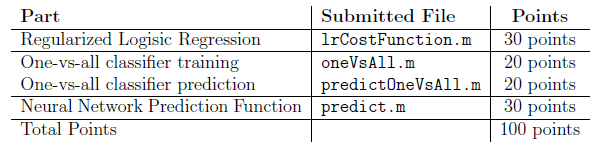

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.